# Group Project

**Input data **

d=readtable('project_housing_data .csv')

d = 21613×20 table
        id             date            price       bedrooms    bathrooms    sqft_living     sqft_lot     floors    sqft_above    sqft_basement    zipcode     lat       long      sqft_living15    sqft_lot15    waterfront    view    condition    grade    yr_built
    __________    _______________    __________    ________    _________    ___________    __________    ______    __________    _____________    _______    ______    

Summarise the table 

summary(d)

Variables:

    id: 21613×1 double

        Values:

            Min       1.0001e+06
            Median    3.9049e+09
            Max          9.9e+09

    date: 21613×1 datetime

        Values:

            Min       20140502T000000
            Median    20141016T000000
            Max       20150527T000000

    price: 21613×1 double

        Values:

            Min         75000 
            Median    4.5e+05 
            Max       7.7e+06 

    bedrooms: 21613×1 double

        Values:

            Min           0   
            Median        3   
            Max          33   

    bathrooms: 21613×1 double

        Values:

            Min            0  
            Median      2.25  
            Max            8  

    sqft_living: 21613×1 double

        Values:

            Min          290  
            Median      1910  
            Max        13540  

    sqft_lot

As we can see, there is no missing value in any attribute. 

# DATA VISUALISATION

Visualise each attribute to better understand data. 

- **Price**: Use histogram to illustrate it. 

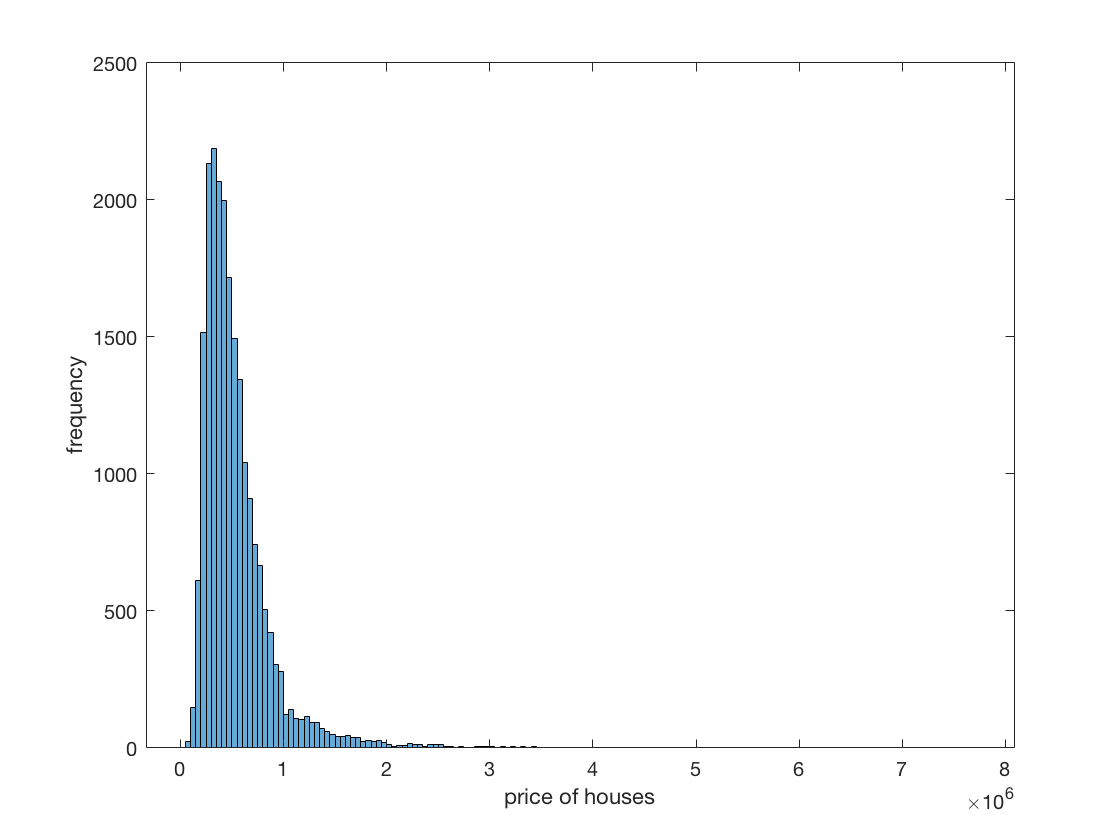

histogram(d.price)
    xlabel('price of houses');
    ylabel('frequency');

Check if it fits the normal distribution 

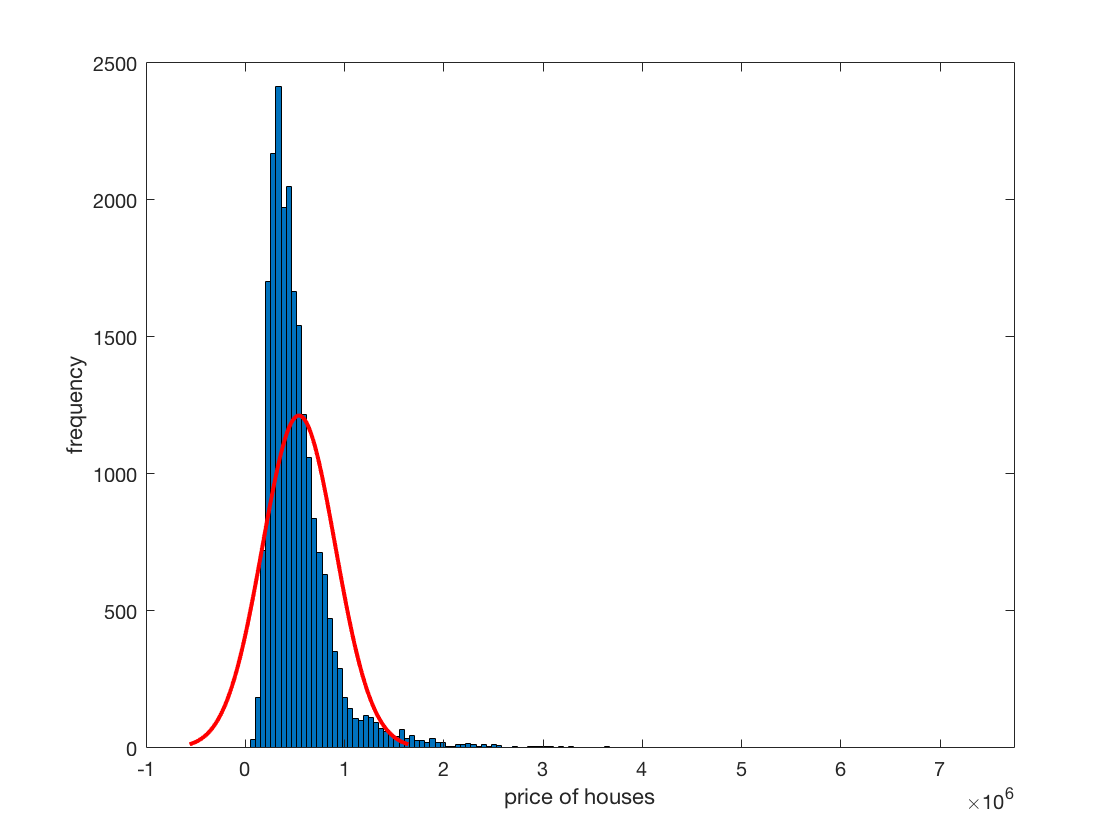

histfit(d.price)
    xlabel('price of houses');
    ylabel('frequency');

The distribution of price seems to be right-skewed. Let's check if it has many outliers

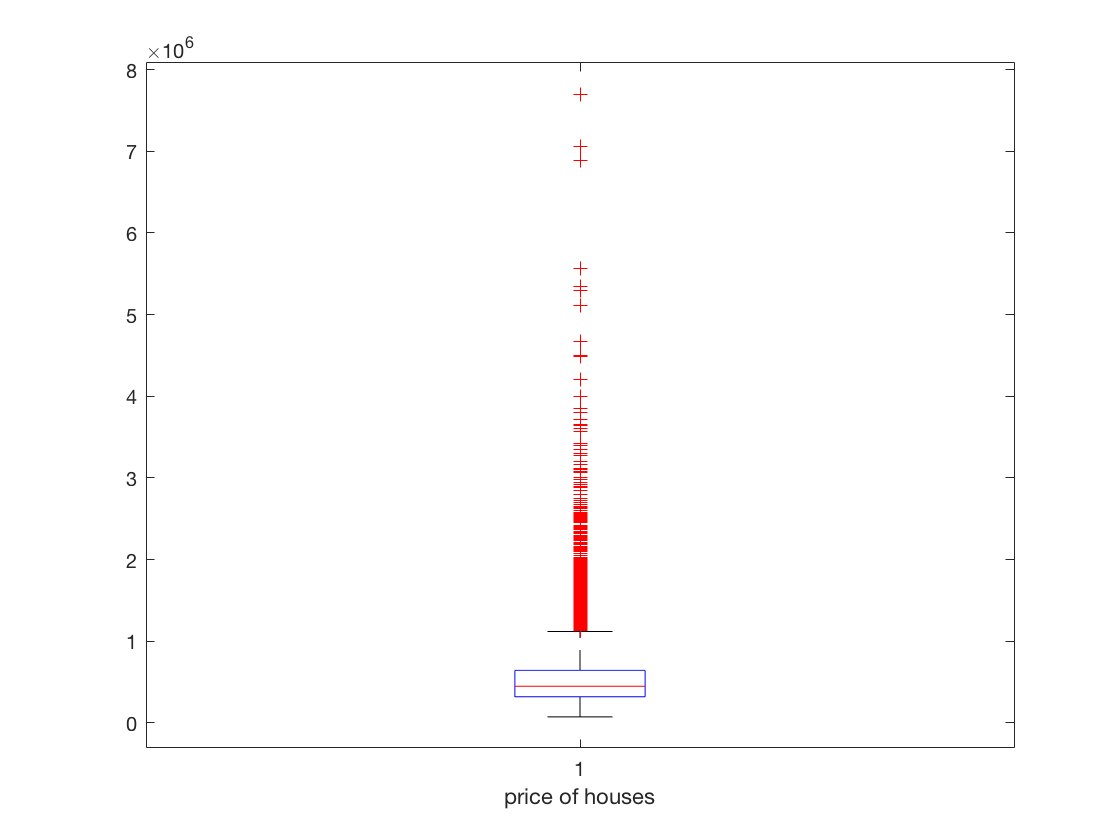

boxplot(d.price)
xlabel('price of houses');

Based on the boxplot, we can see this attribute has many outliers. It has total 1159 outliers. We can also see its min-max values and its quartiles. Let's see its mean and mode value. 

mean(d.price)

ans = 5.4018e+05

mode(d.price)

ans = 350000

The mean price is 540 000 and the mode value is 350 000. After the outlier cleaning, the mean may change.           

        **  2. Bedrooms: **

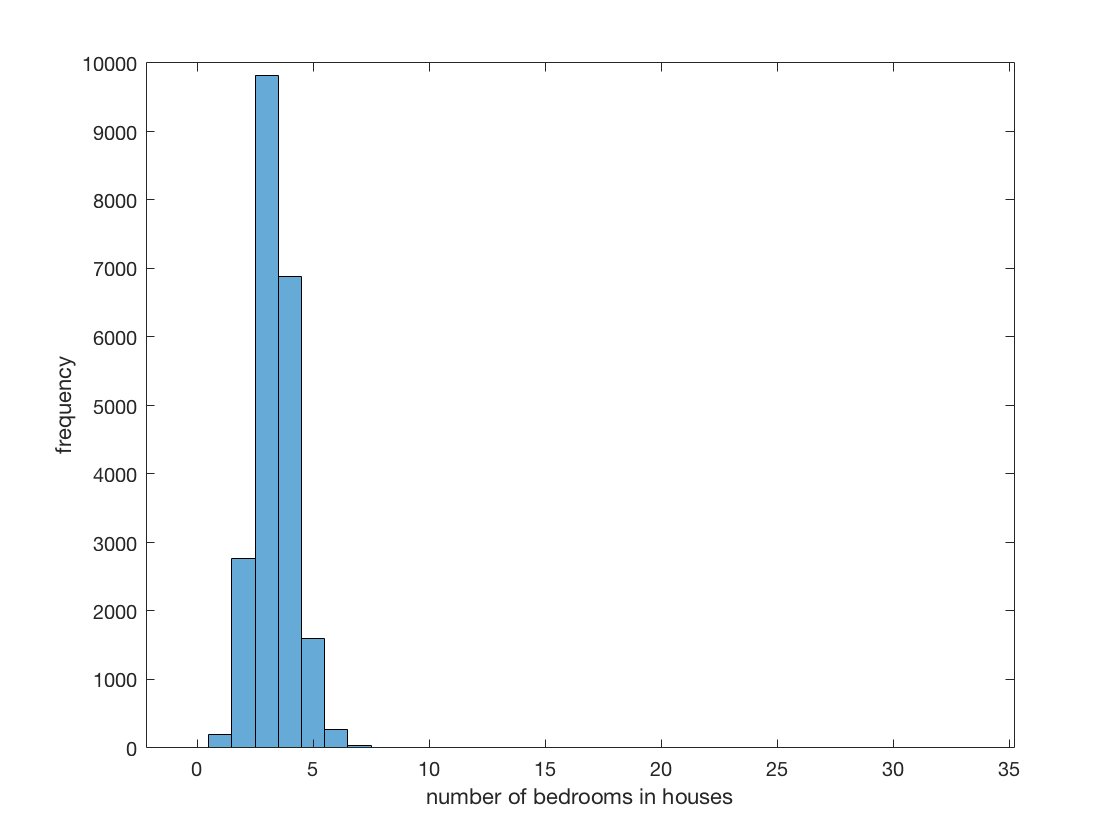

histogram(d.bedrooms) 
    xlabel('number of bedrooms in houses');
    ylabel('frequency');

According to the histogram, the graph is a right-skewed distribution. Let's check the outliers with the boxplot. 

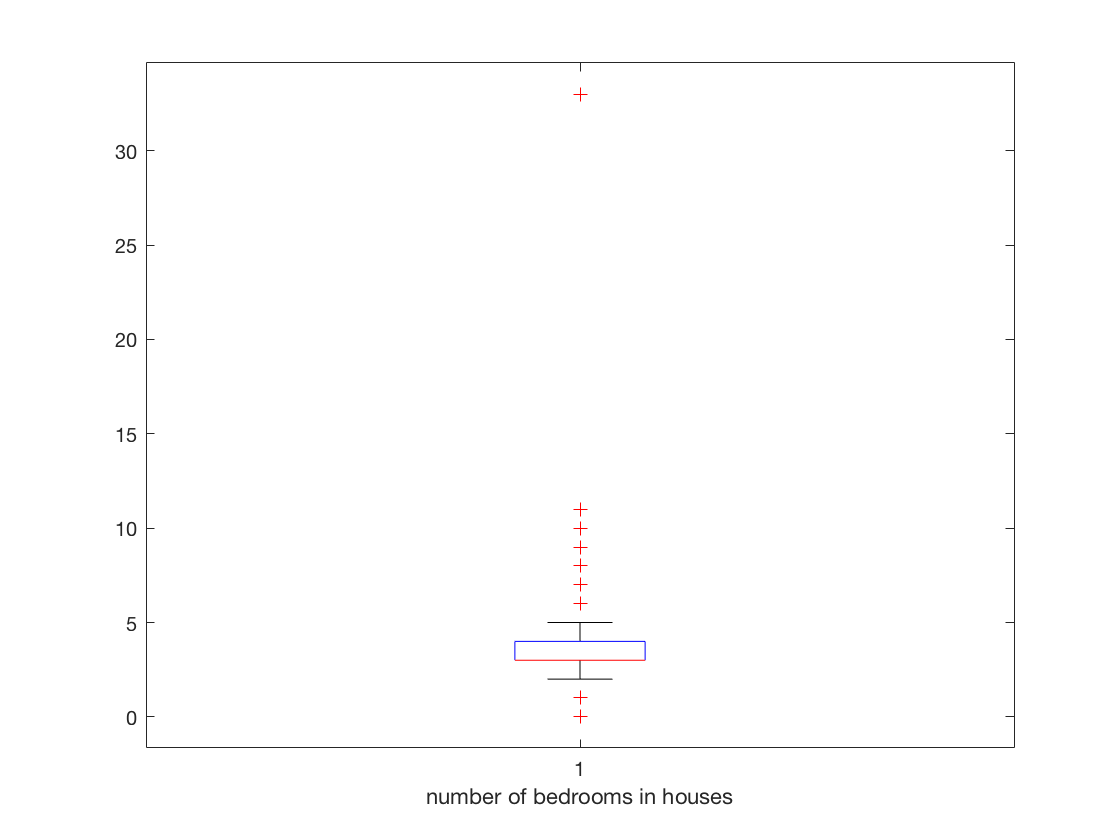

boxplot(d.bedrooms)
    xlabel('number of bedrooms in houses')

Based on the boxplot, there is 1 outlier with the value 33. This doesn't make sense, we will clean the outlier data when we finish analyzing all variables.

mean(d.bedrooms)

ans = 3.3708

mode(d.bedrooms)

ans = 3

 The mean number of bedrooms in houses is 3.37 and the mode value is 3. 

         **   3. Bathrooms**

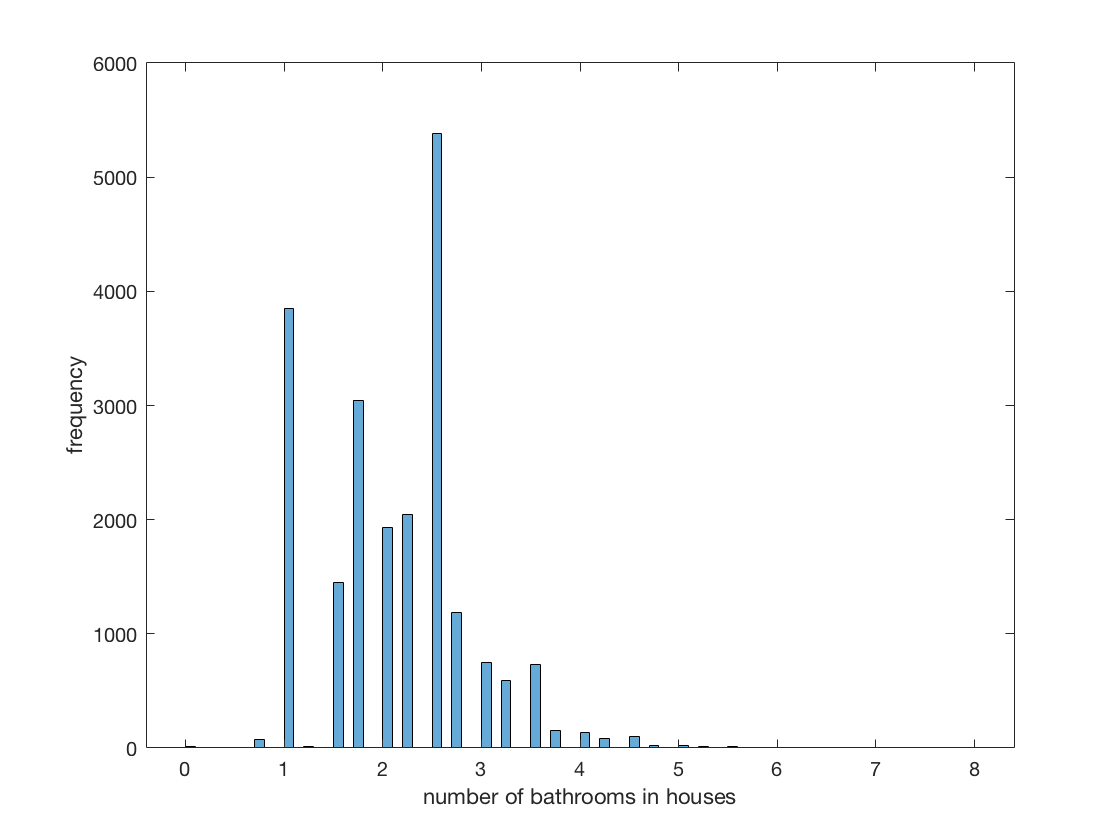

histogram(d.bathrooms) 
xlabel('number of bathrooms in houses');
ylabel('frequency');

Let's have a look at boxplot to see it clearer. 

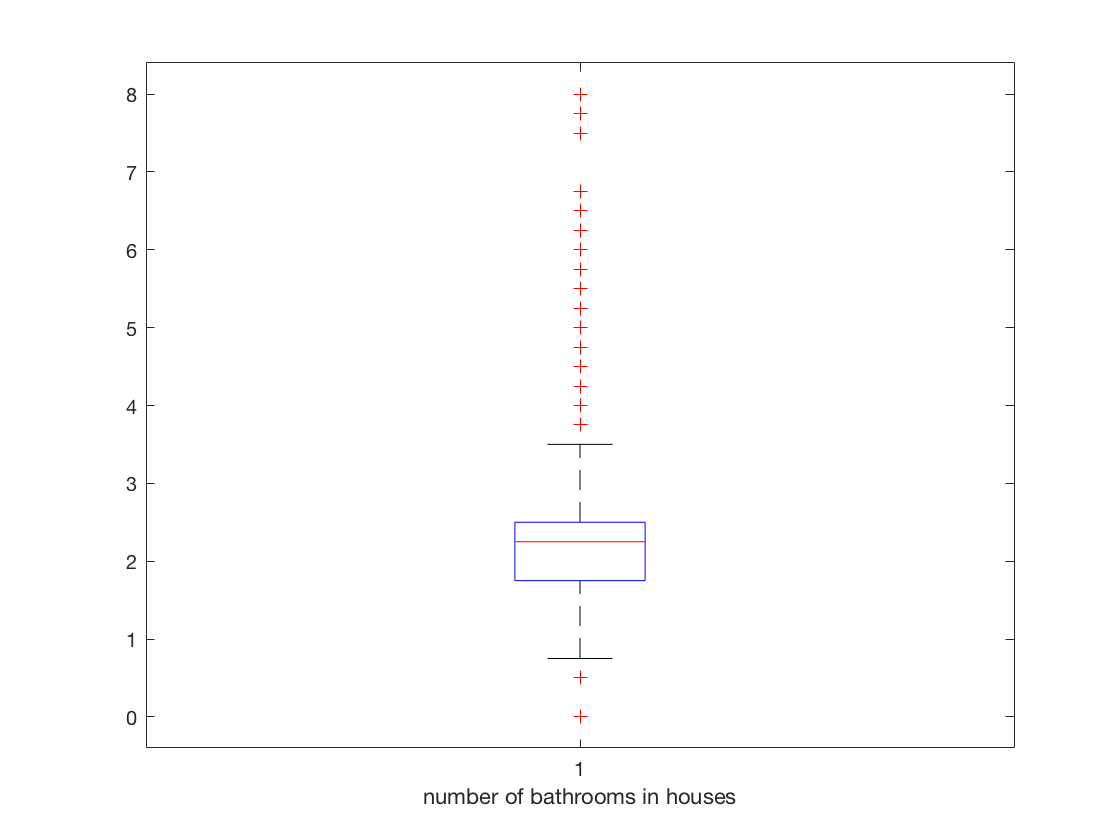

boxplot(d.bathrooms)
xlabel('number of bathrooms in houses')

There are outliers below and above the quantile. We will remove it. 

mean(d.bathrooms)

ans = 2.1148

mode(d.bathrooms)

ans = 2.5000

 The mean number of bathrooms in houses is 2.11 and the mode value is 2.5. 

           ** 4. Square feet living (sqft_living) **

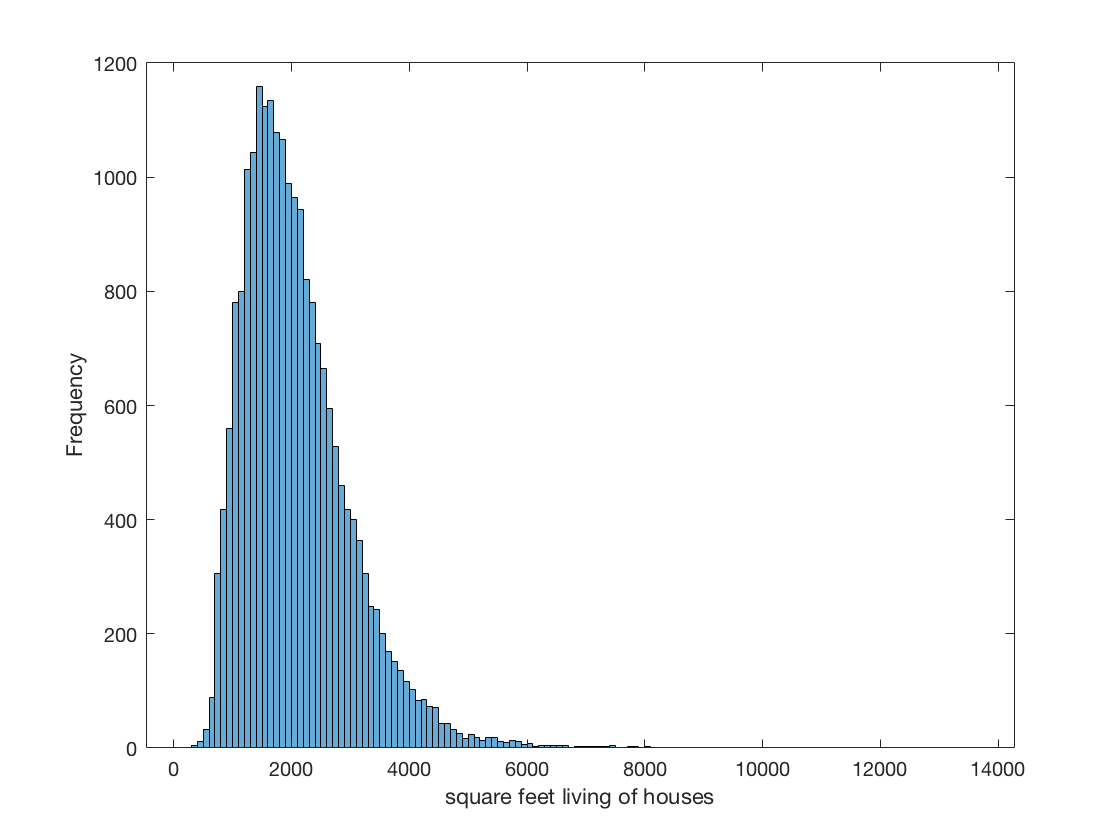

histogram(d.sqft_living) 
    xlabel('square feet living of houses')
    ylabel('Frequency') 

The boxplot as well. 

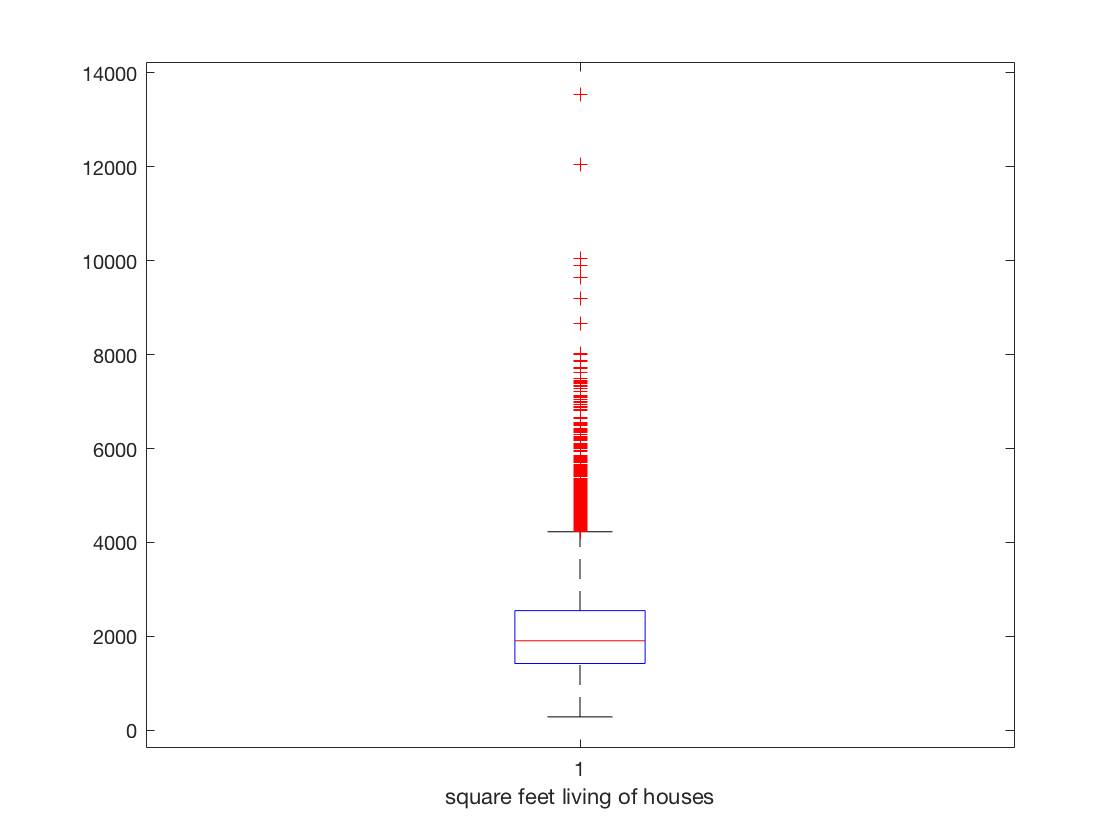

boxplot(d.sqft_living) 
xlabel('square feet living of houses')

And also check out the mean and mode value 

[mean(d.sqft_living) mode(d.sqft_living)]

ans = 	1.0e+03 *

    2.0799    1.3000


The mean square feet living is 2 079 and its mode value is 1 300. 

          **  5. Square feet lot (sqft_lot):**

Histogram: 

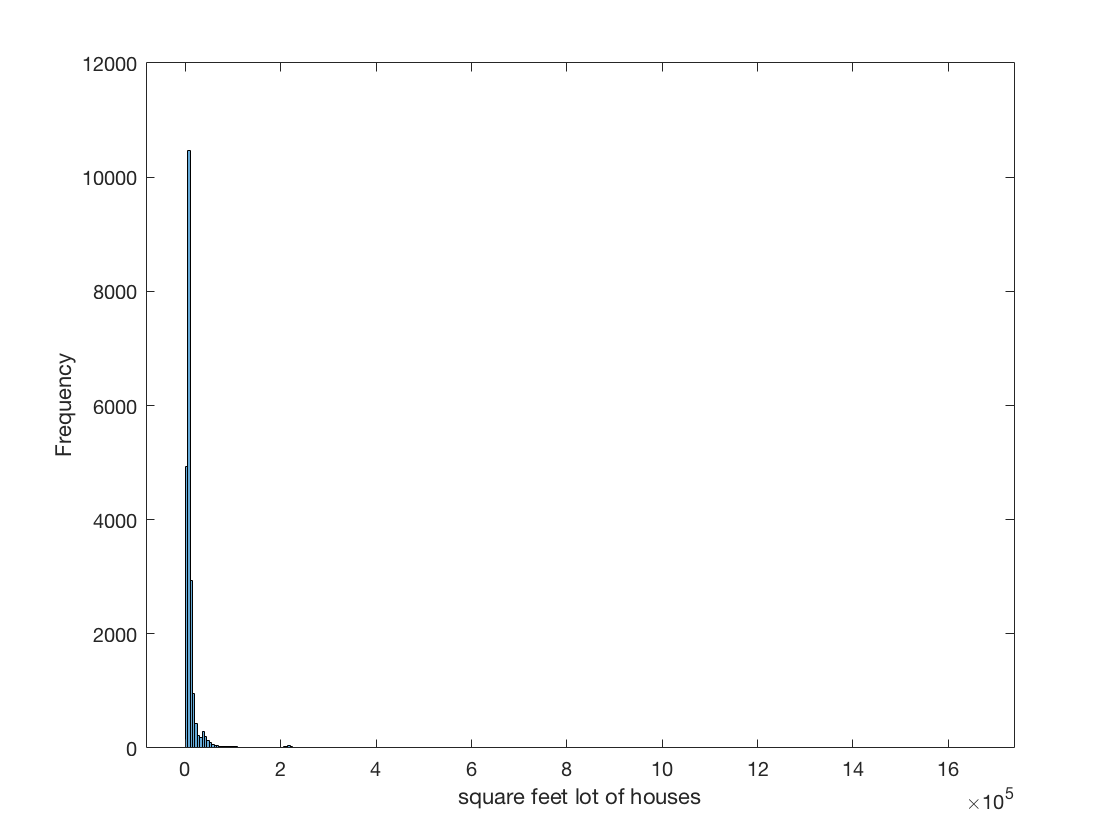

histogram(d.sqft_lot)
xlabel('square feet lot of houses')
ylabel('Frequency')

Boxplot: 

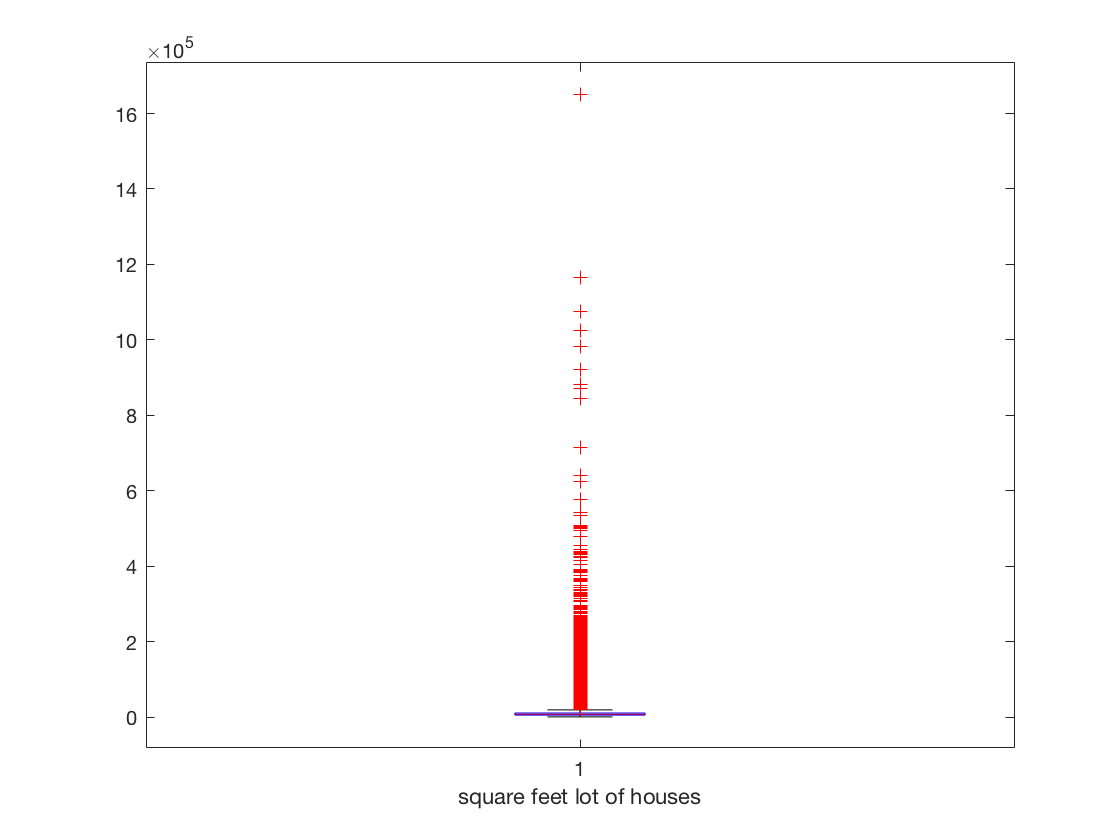

boxplot(d.sqft_lot)
xlabel('square feet lot of houses')  

Mean and mode value 

[mean(d.sqft_lot) mode(d.sqft_lot)]

ans = 	1.0e+04 *

    1.5107    0.5000


The mean square feet of the land lot is 15 107 and the mode value is 5000.  

           **6. Floors: **

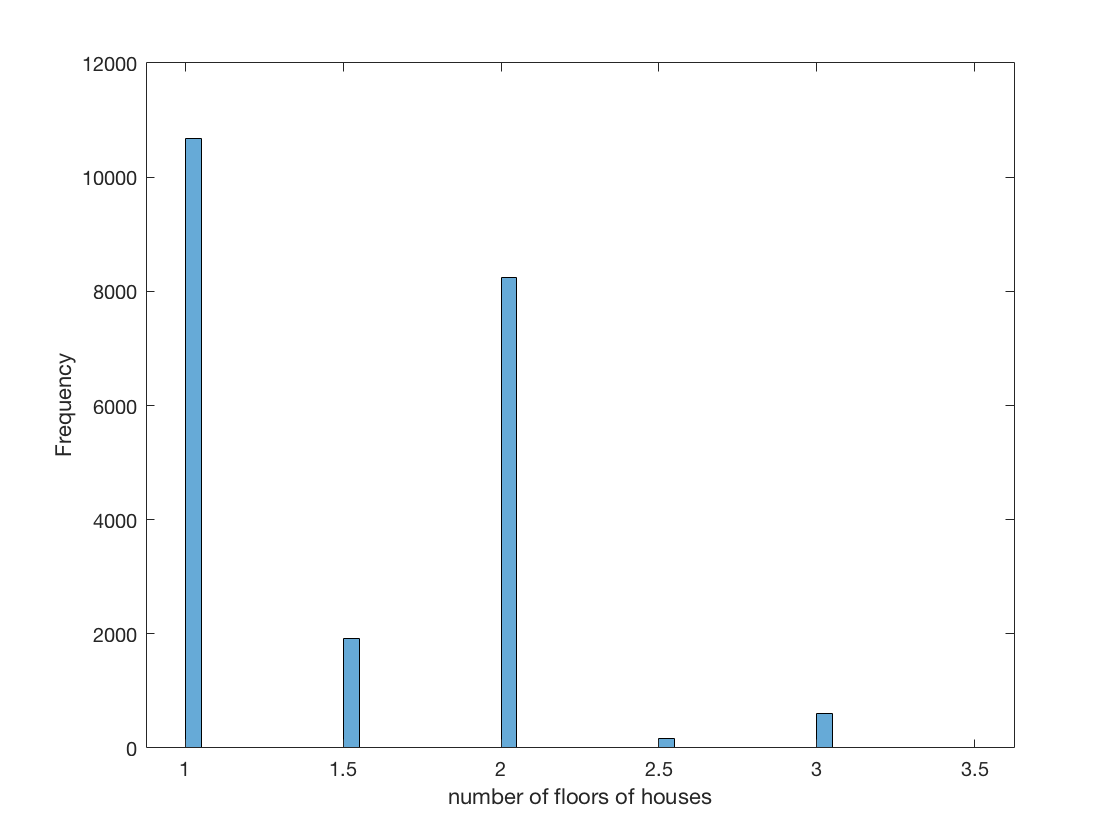

histogram(d.floors) 
xlabel('number of floors of houses')
ylabel('Frequency')   

The graph looks good. Most of the houses has 1 floor, the second most number of floors is 2.

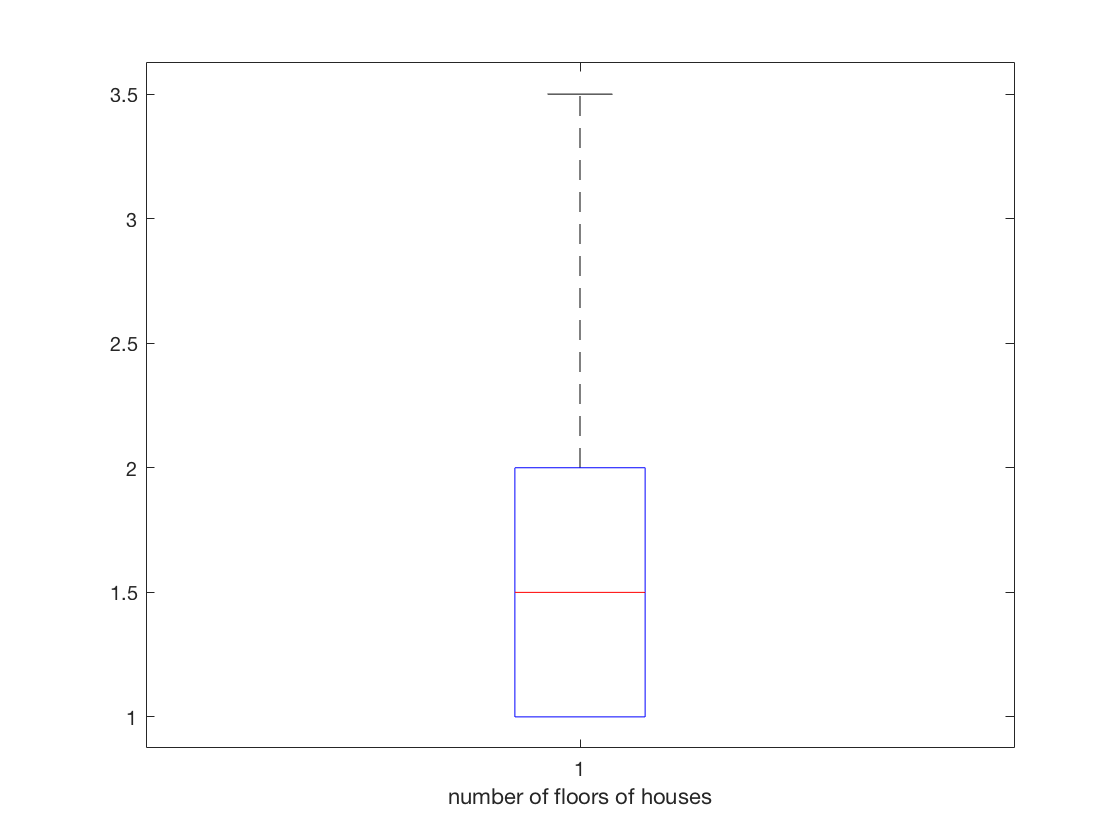

boxplot(d.floors) 
xlabel('number of floors of houses')

This attribute doesn't have any outlier. 

So, in general, price, square feet livng and square feet lot variable have upper outliers, bedrooms and bathrooms have outliers above and below the quantile while floors have no outlier. 

Mean and mode value: 

[mean(d.floors) mode(d.floors)]

ans =     1.4943    1.0000


The mean number of floors in houses is 1.49 and the mode value is 1. 

           ** 7. Square feet above (sqft_above)**

Histogram: 

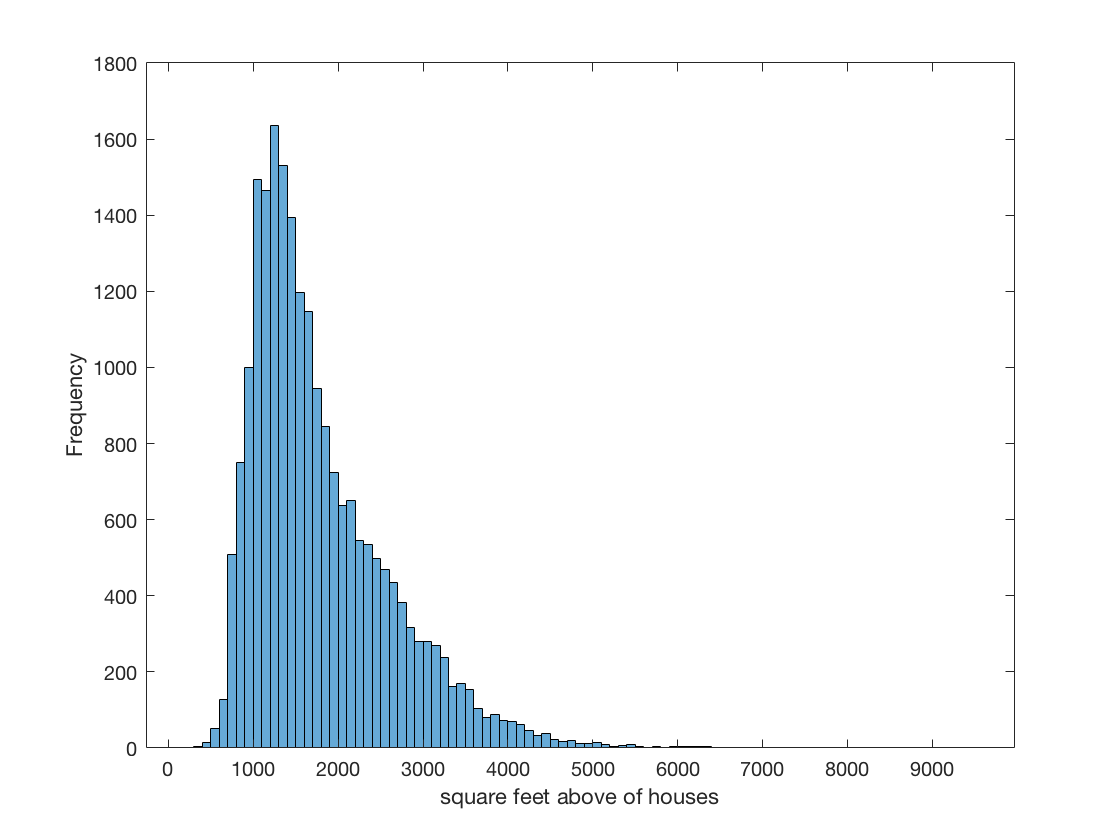

histogram(d.sqft_above) 
    xlabel('square feet above of houses')
    ylabel('Frequency')

Boxplot: 

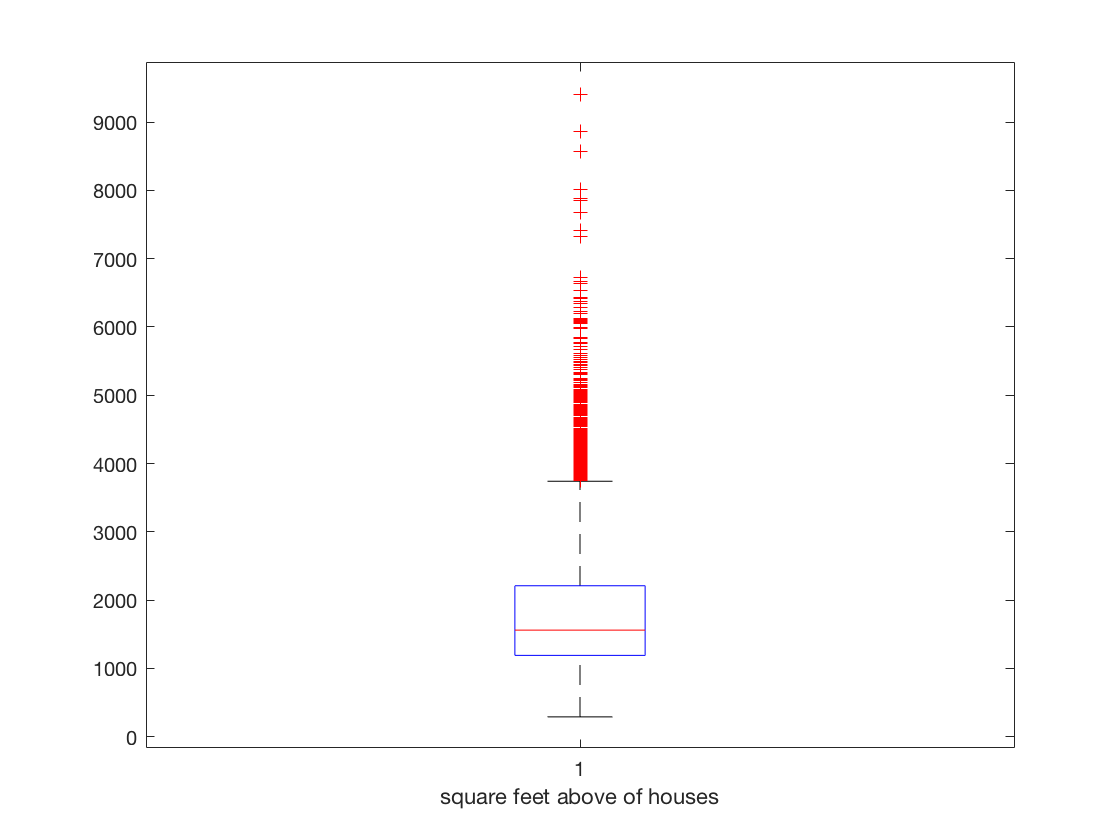

boxplot(d.sqft_above) 
    xlabel('square feet above of houses')

Mean and mode value 

    [mean(d.sqft_above) mode(d.sqft_above)]

ans = 	1.0e+03 *

    1.7884    1.3000


         ** 8. Square feet basement (sqft_basement)**

Histogram: 

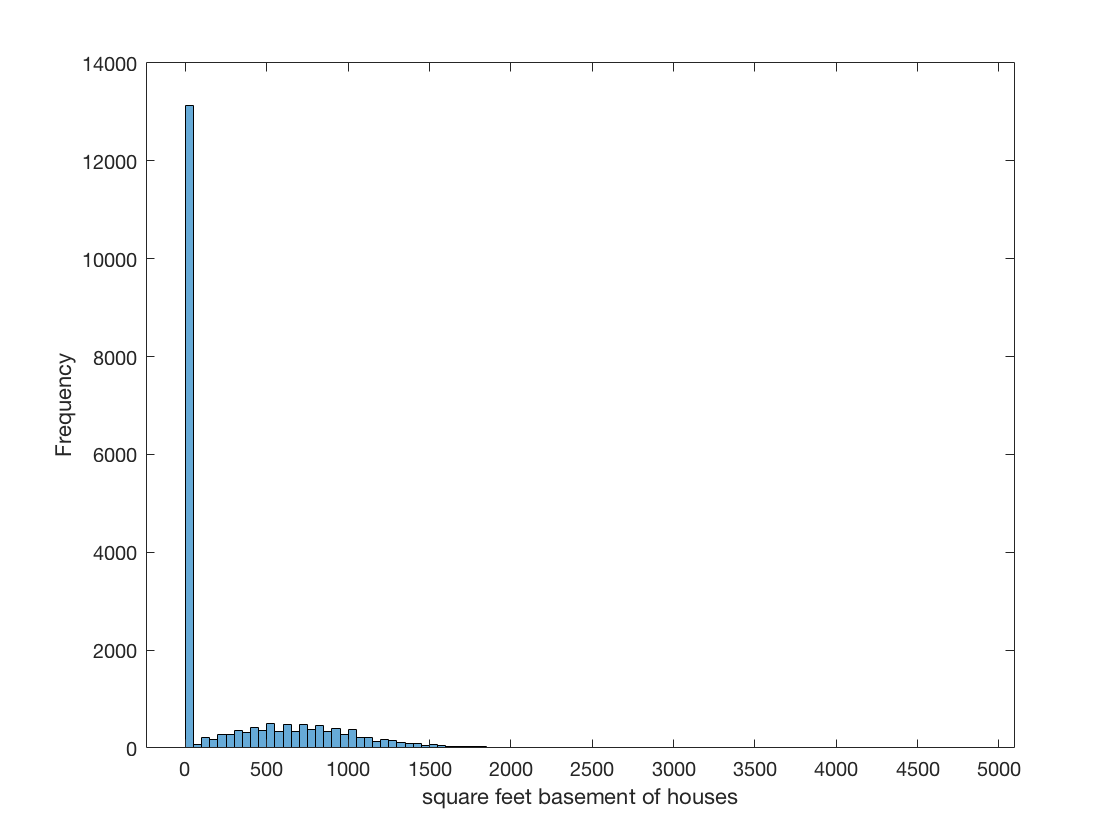

histogram(d.sqft_basement) 
    xlabel('square feet basement of houses')
    ylabel('Frequency') 

Boxplot: 

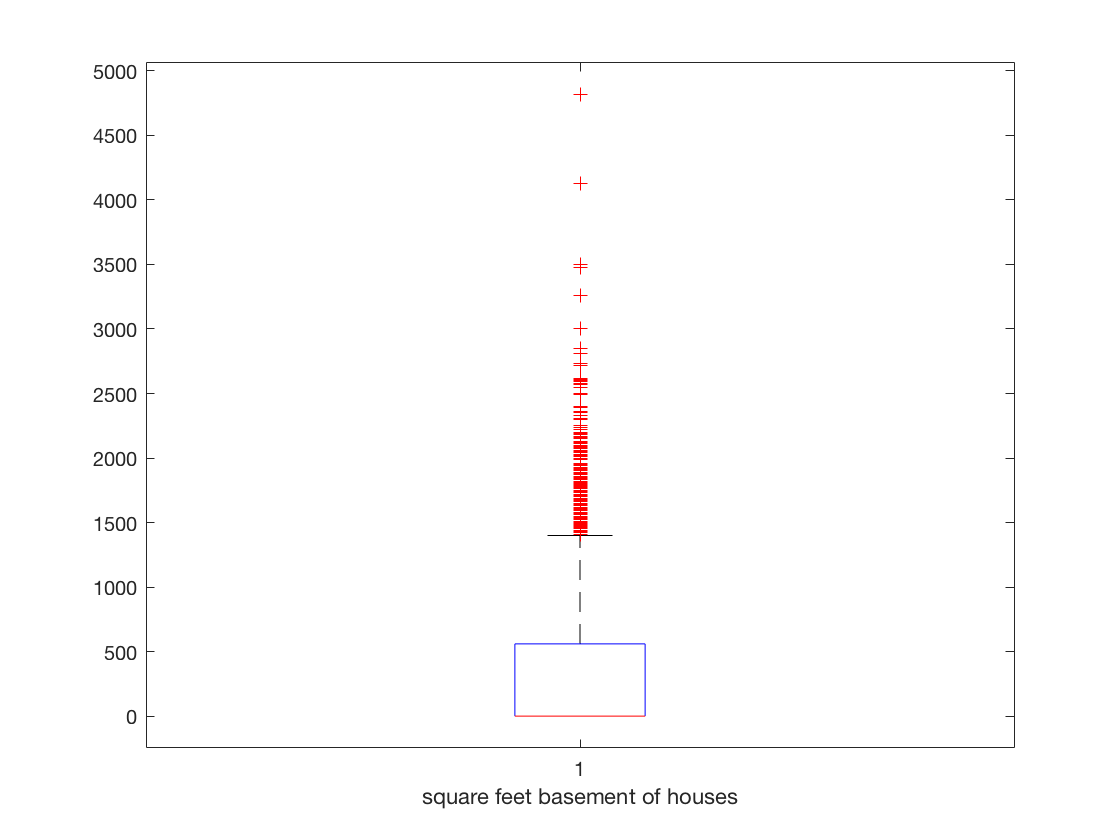

boxplot(d.sqft_basement)
    xlabel('square feet basement of houses') 

Mean and mode value

[mean(d.sqft_basement) mode(d.sqft_basement)]

ans =   291.5090         0


         ** 9. Zipcode:**

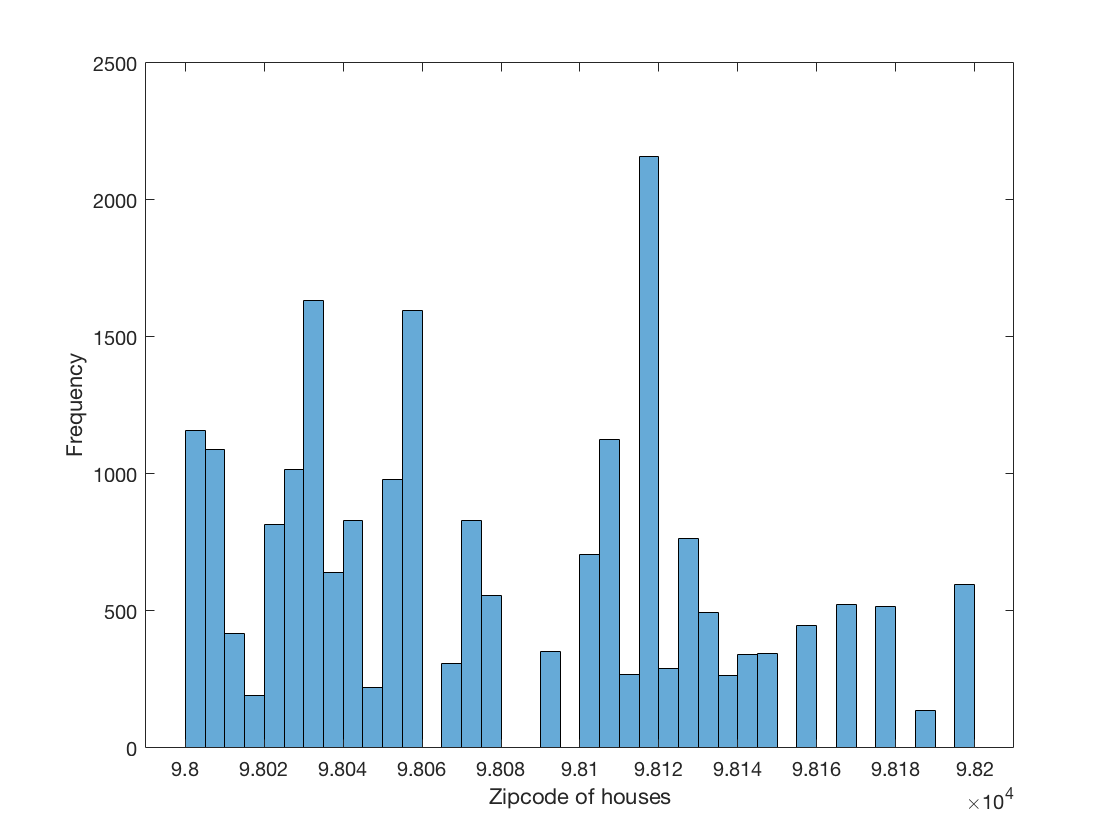

histogram(d.zipcode) 
    xlabel('Zipcode of houses')
    ylabel('Frequency')

As it is a categorical variable, let's see the summary of it. 

summary(categorical(d.zipcode))

     98001      362 
     98002      199 
     98003      280 
     98004      317 
     98005      168 
     98006      498 
     98007      141 
     98008      283 
     98010      100 
     98011      195 
     98014      124 
     98019      190 
     98022      234 
     98023      499 
     98024       81 
     98027      412 
     98028      283 
     98029      321 
     98030      256 
     98031      274 
     98032      125 
     98033      432 
     98034      545 
     98038      590 
     98039       50 
     98040      282 
     

mode(d.zipcode)

ans = 98103

The mode zipcode appears in the data set is 98103. 

         **10. Lat: **

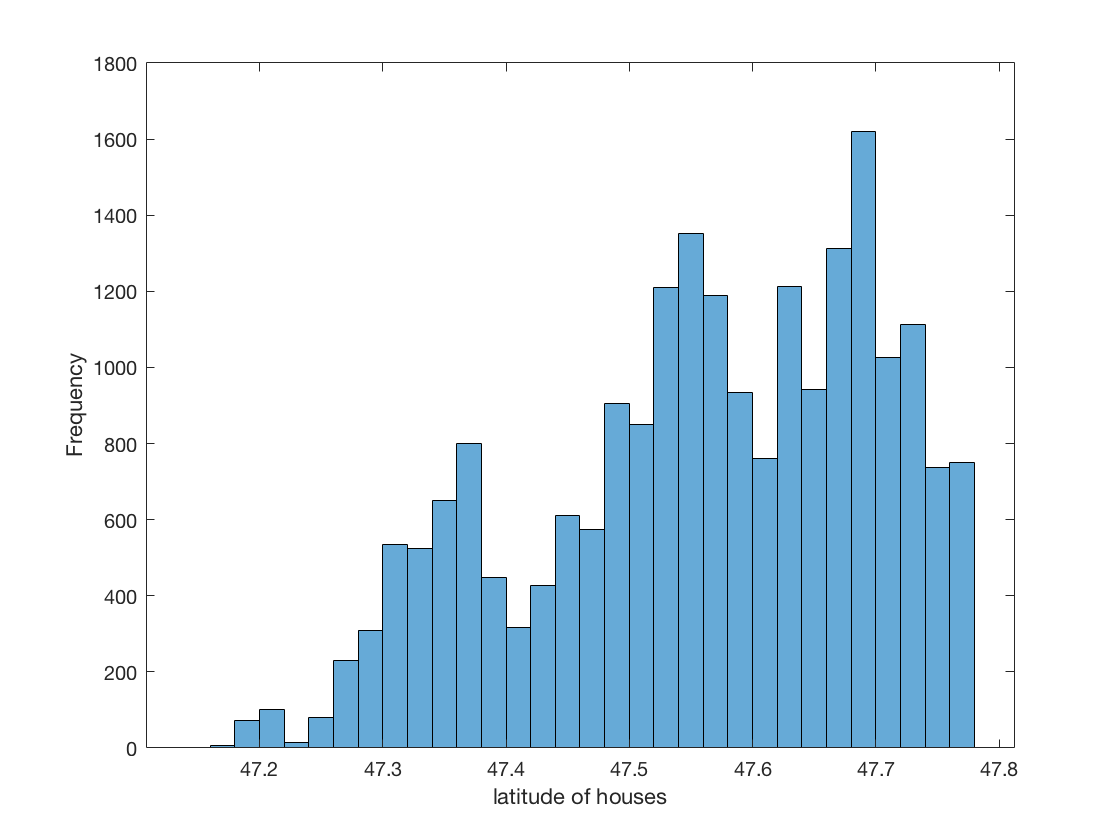

histogram(d.lat) 
    xlabel('latitude of houses')
    ylabel('Frequency')

        ** 11. Long: **

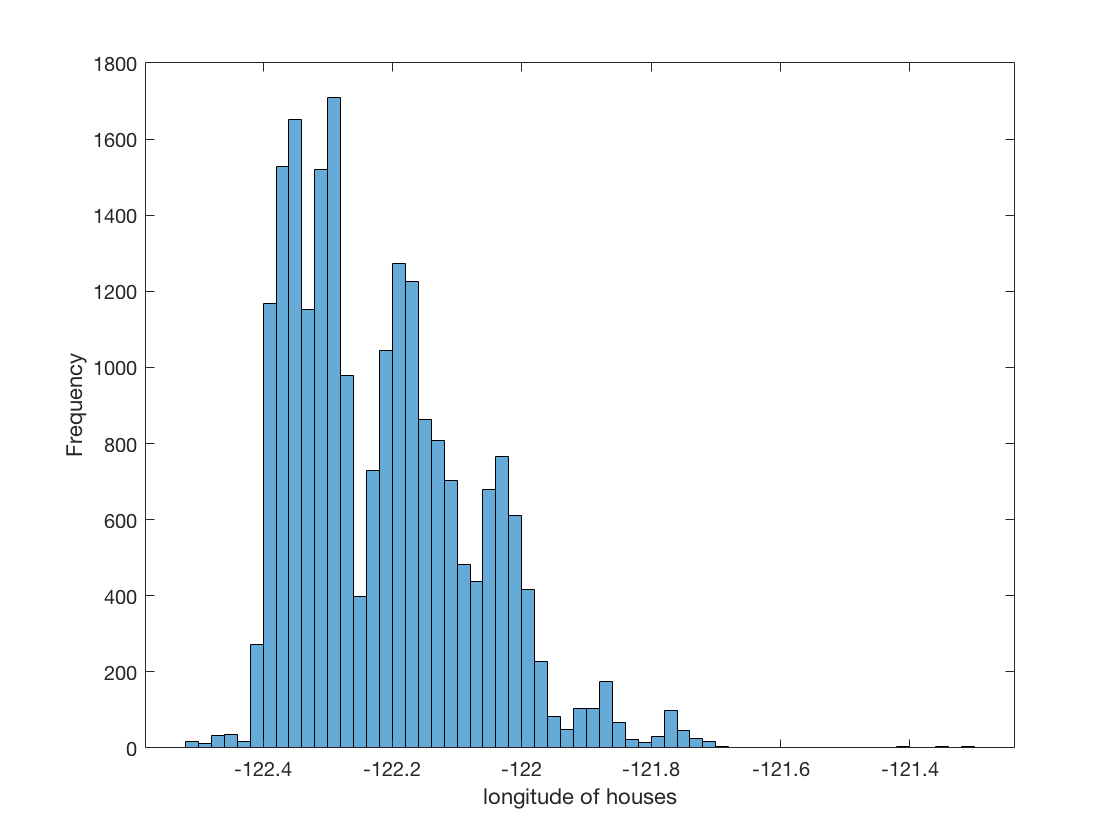

histogram(d.long) 
    xlabel('longitude of houses')
    ylabel('Frequency') 

       ** 12. Square feet living for the nearest 15 neighbours (sqft_living15)**

Histogram: 

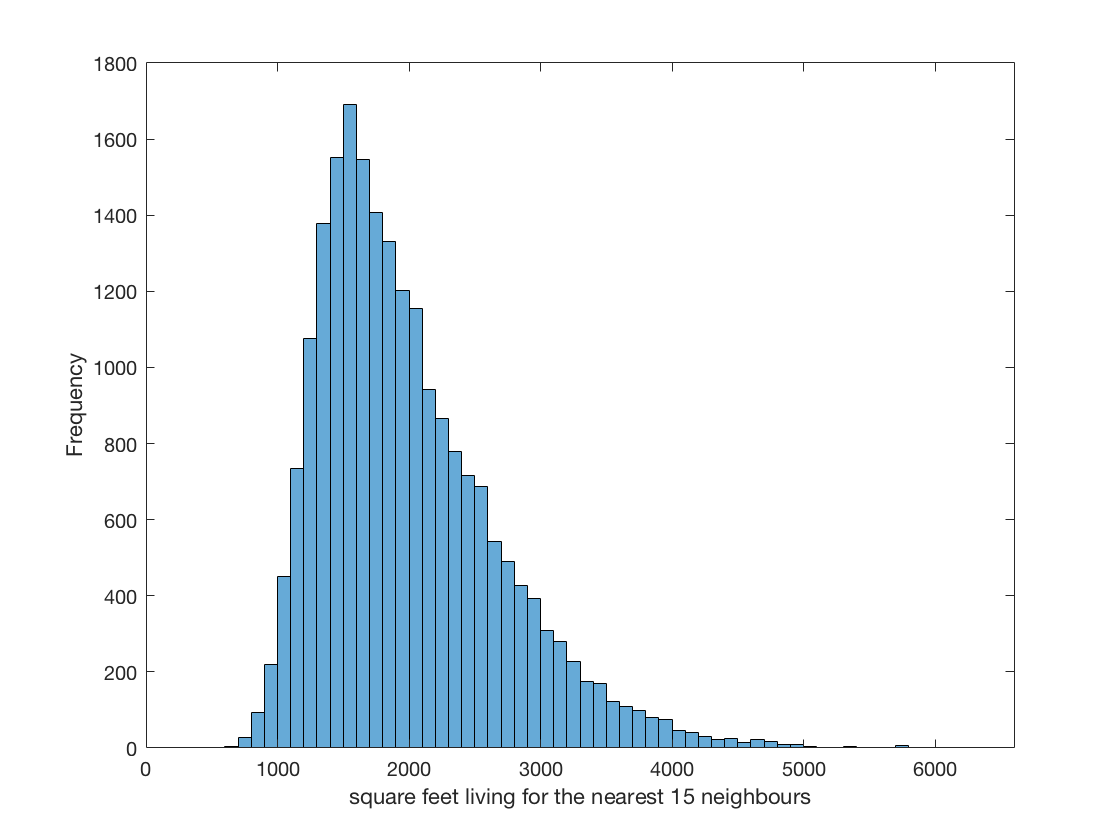

histogram(d.sqft_living15) 
    xlabel('square feet living for the nearest 15 neighbours')
    ylabel('Frequency')

Boxplot: 

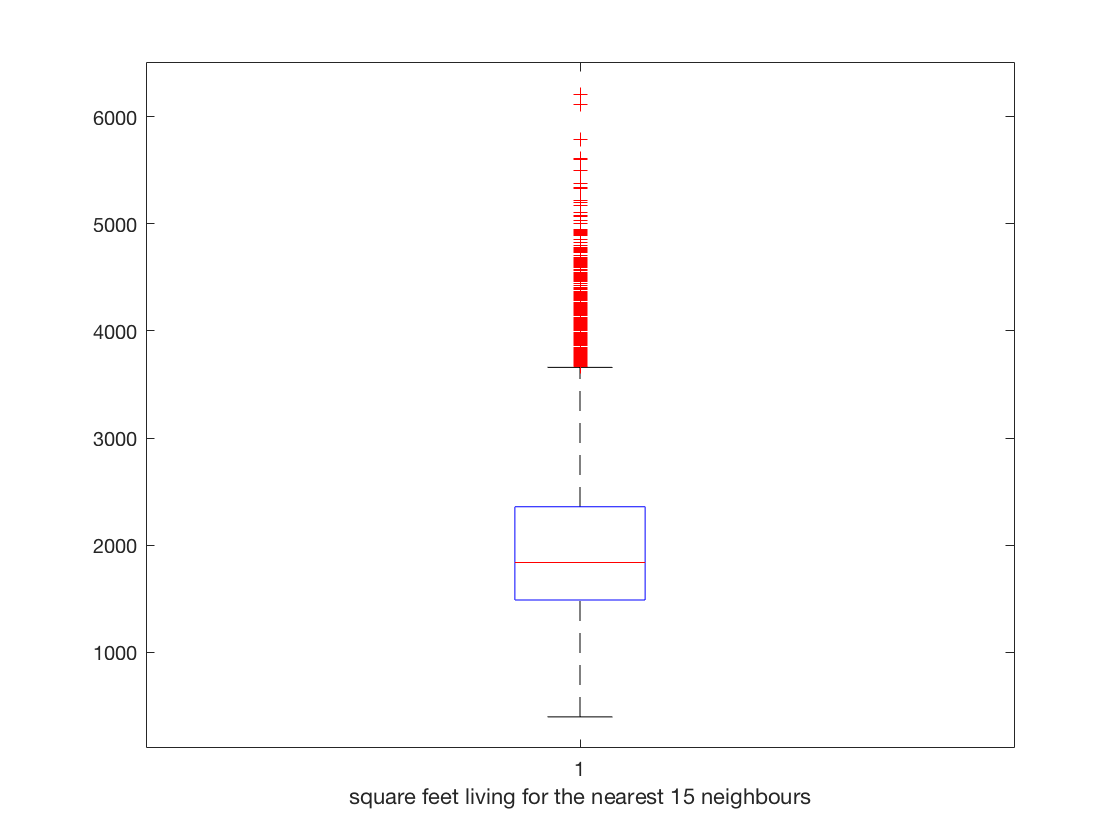

boxplot(d.sqft_living15) 
    xlabel('square feet living for the nearest 15 neighbours')

It seems to have quite a lot outliers in the upper part of the quantile. 

Mean and mode value: 

[mean(d.sqft_living15) mode(d.sqft_living15)]    

ans = 	1.0e+03 *

    1.9866    1.5400


            **13. Square feet lot for the nearest 15 neighbours (sqft_lot15)**

Histogram: 

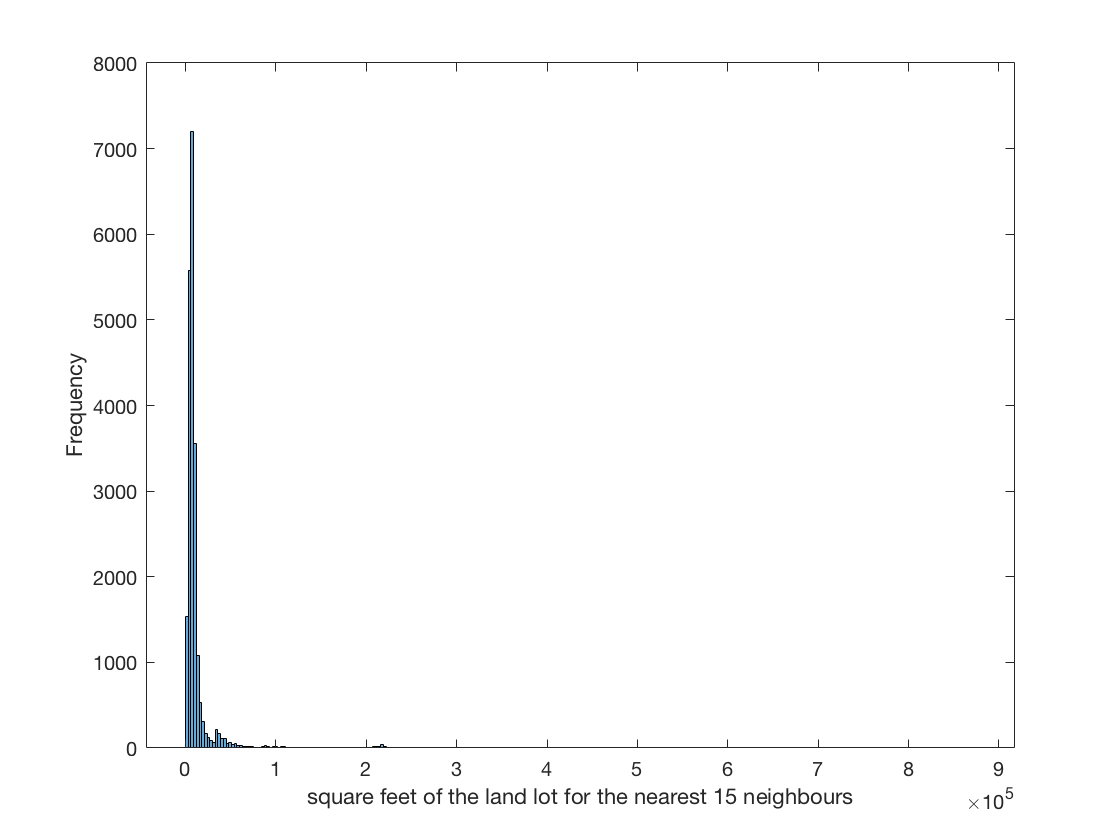

histogram(d.sqft_lot15) 
    xlabel('square feet of the land lot for the nearest 15 neighbours')
    ylabel('Frequency') 

Boxplot: 

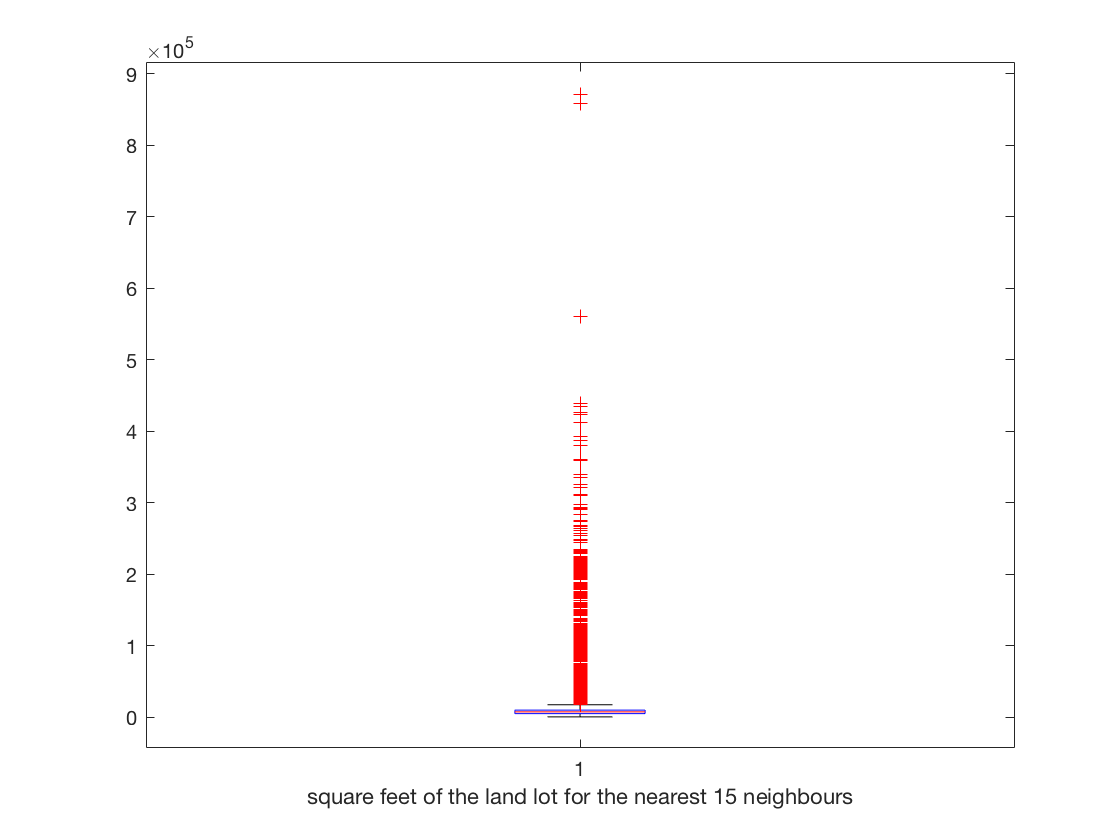

boxplot(d.sqft_lot15) 
    xlabel('square feet of the land lot for the nearest 15 neighbours') 

Mean and mode value: 

[mean(d.sqft_lot15) mode(d.sqft_lot15)]   

ans = 	1.0e+04 *

    1.2768    0.5000


        **  14. Waterfront: **

summary(categorical(d.waterfront))

     0      21450 
     1        163 


We use pie chart to illustrate the data: 

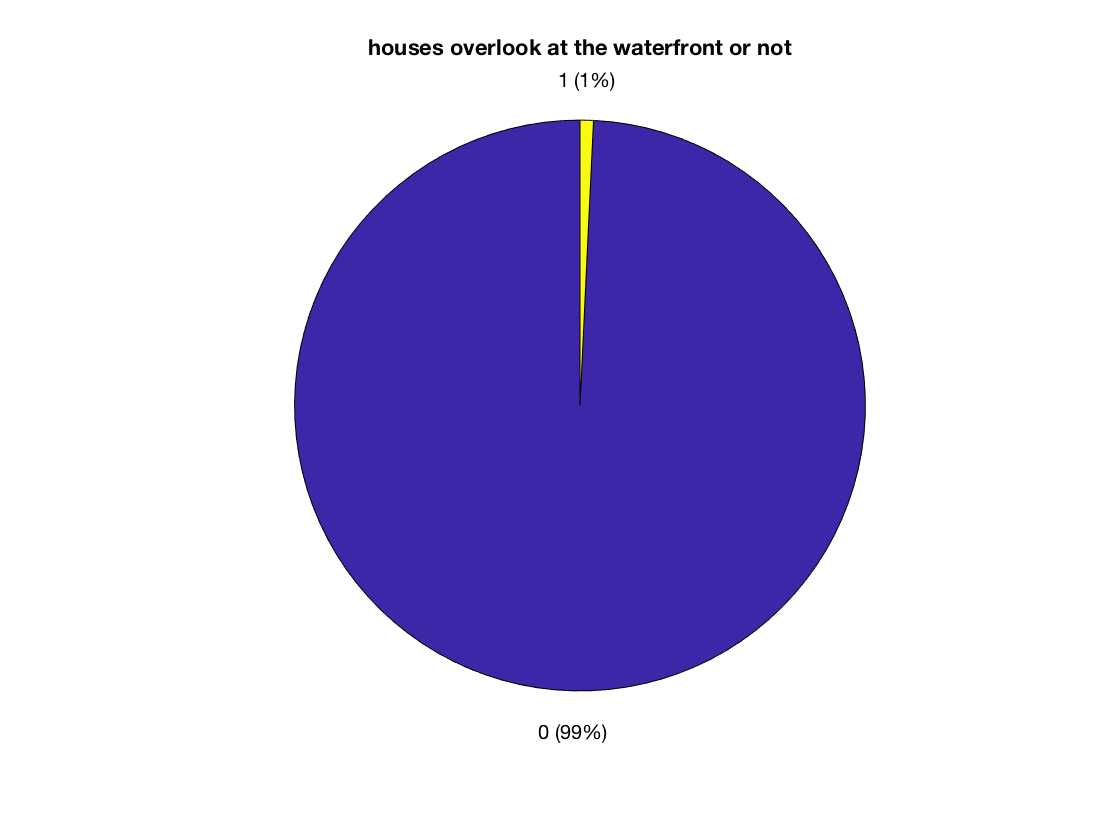

pie(categorical(d.waterfront));
title('houses overlook at the waterfront or not')

 Most of the house doesn't overlook the waterfront with 21450 houses over total, accounts for 99.2%. Only 1% of houses does.

           **15. View: **

summary(categorical(d.view))

     0      19489 
     1        332 
     2        963 
     3        510 
     4        319 


Let's have a look at the pie chart: 

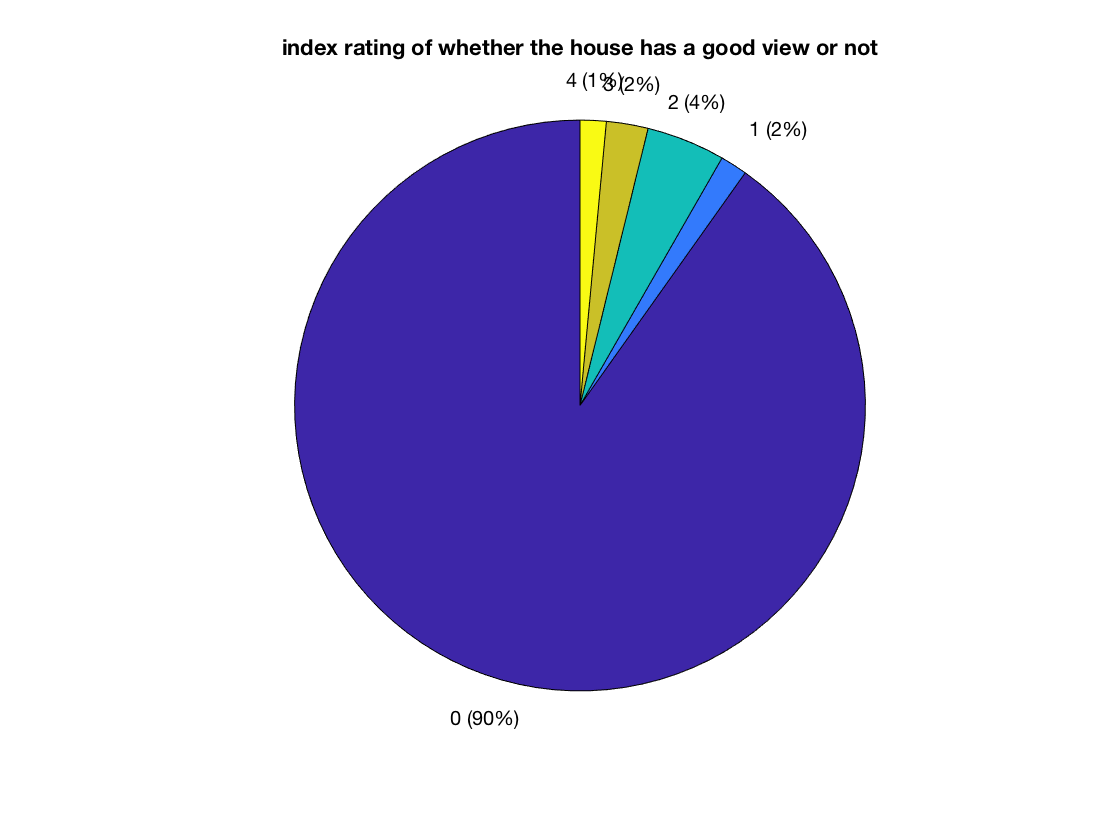

pie(categorical(d.view))
    title('index rating of whether the house has a good view or not')

19489 houses have no good view over total, accounts for 90%. 

          **  16. Condition: **

summary(categorical(d.condition))

     1         30 
     2        172 
     3      14031 
     4       5679 
     5       1701 


Let's have a look at the pie chart: 

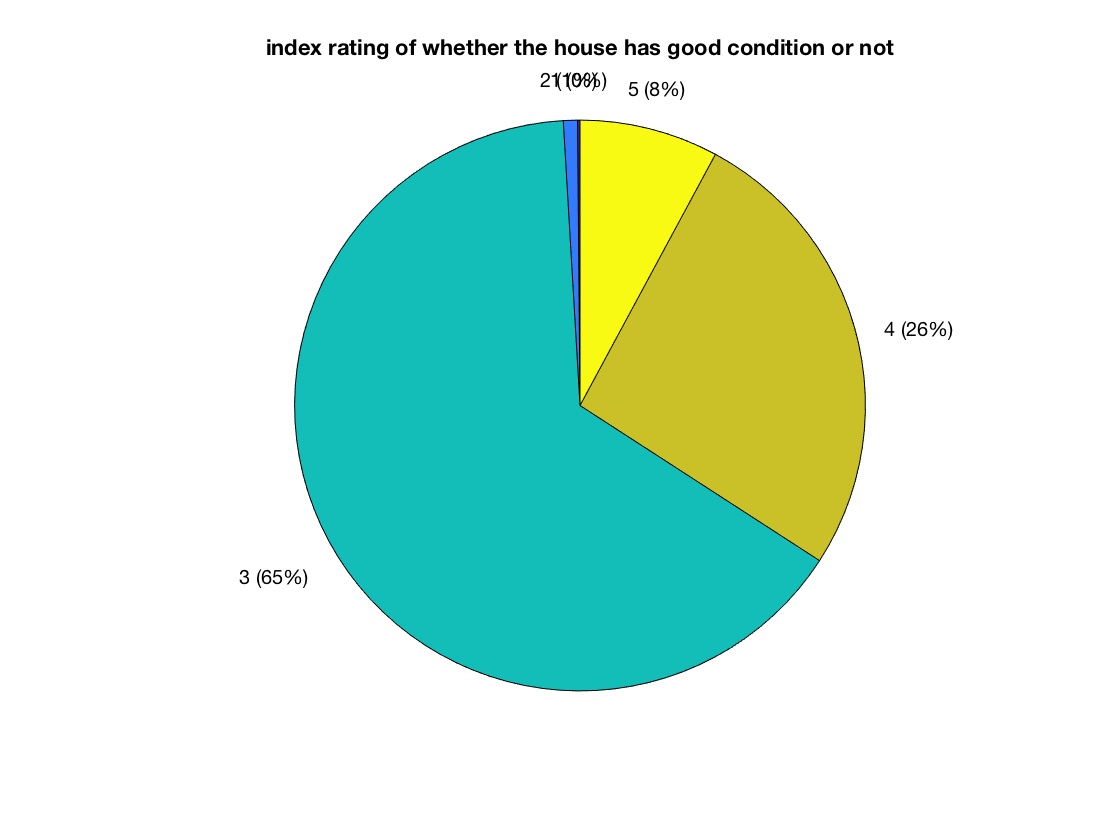

pie(categorical(d.condition))
    title('index rating of whether the house has good condition or not')

Based on the pie chart, 65% of houses have average condition. Better than average conditions have higher proportion than the lower part. 

            **17. Grade: **

summary(categorical(d.grade))

     1          1 
     3          3 
     4         29 
     5        242 
     6       2038 
     7       8981 
     8       6068 
     9       2615 
     10      1134 
     11       399 
     12        90 
     13        13 


Let's check the histogram: 

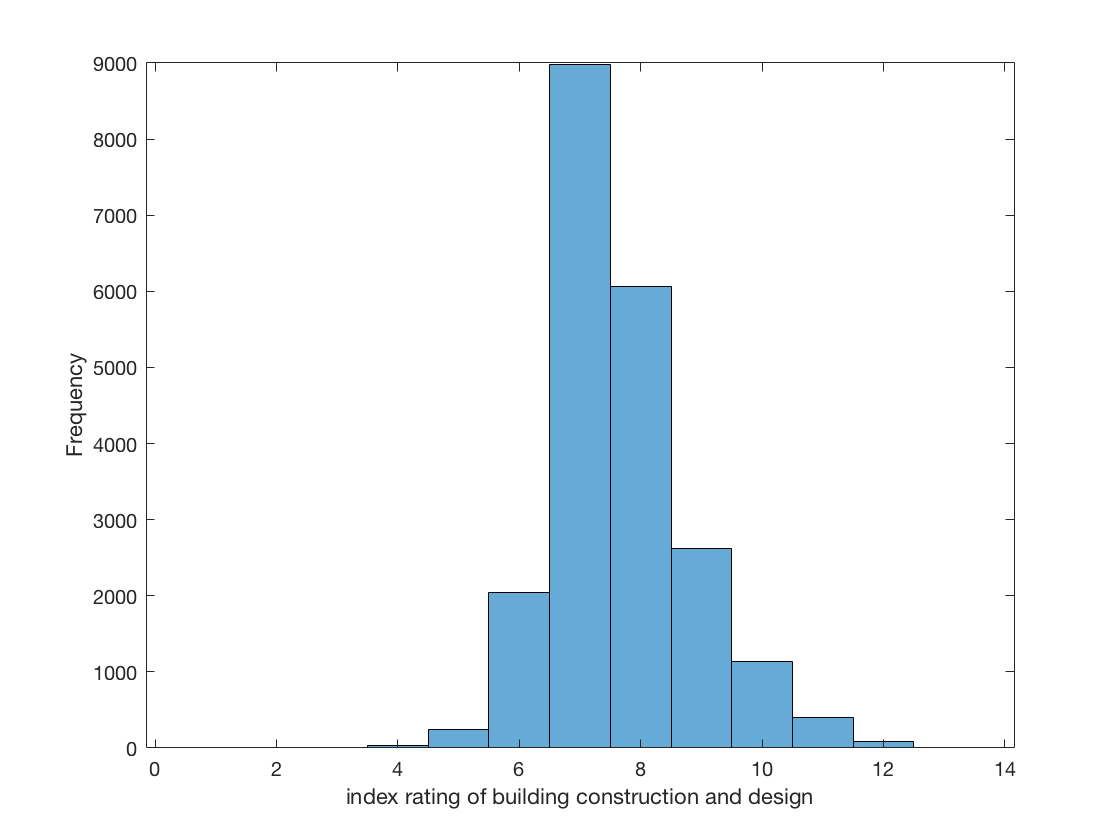

histogram(d.grade) 
    xlabel('index rating of building construction and design')
    ylabel('Frequency')

Grade 7 is the median and the mode of this attribute. 

         ** 18. Year built (yr_built)**

summary(categorical(d.yr_built))

     1900       87 
     1901       29 
     1902       27 
     1903       46 
     1904       45 
     1905       74 
     1906       92 
     1907       65 
     1908       86 
     1909       94 
     1910      134 
     1911       73 
     1912       79 
     1913       59 
     1914       54 
     1915       64 
     1916       79 
     1917       56 
     1918      120 
     1919       88 
     1920       98 
     1921       76 
     1922       95 
     1923       84 
     1924      139 
     1925      165 
     1926      180 
 

Histogram: 

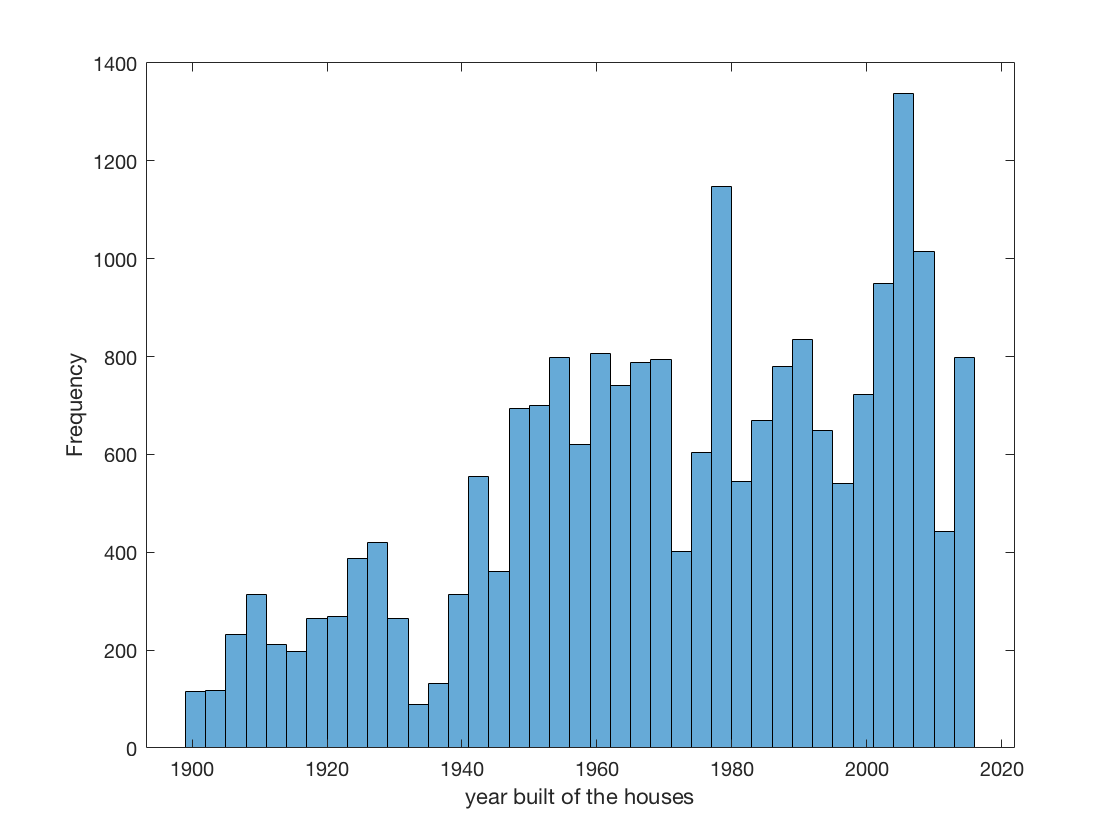

histogram(d.yr_built) 
    xlabel('year built of the houses')
    ylabel('Frequency')

According to the histogram, the period 2004-2007 has the most hosues built. 

## CLEANING OUTLIERS 

d.id=[]; d.date=[]; a=d;
for i = [1:5 7 8 11:13]
    a.(i)= filloutliers(d.(i),'linear','quartiles');
end 

Now d is the original table and a is the cleaned table. 

# DATA GROUPING AND ANALYZING

First, set the function: 

mystats=@(x)[min(x) mean(x) max(x)];

Now compare price in different groups of categorical variables: 

           ** 1. Waterfront: **

[grpW,WVals] = findgroups(a.waterfront);
statspricewaterfront=splitapply(mystats,a.price,grpW)

statspricewaterfront = 	1.0e+06 *

    0.0750    0.4763    1.1200
    0.2045    0.5500    1.1000


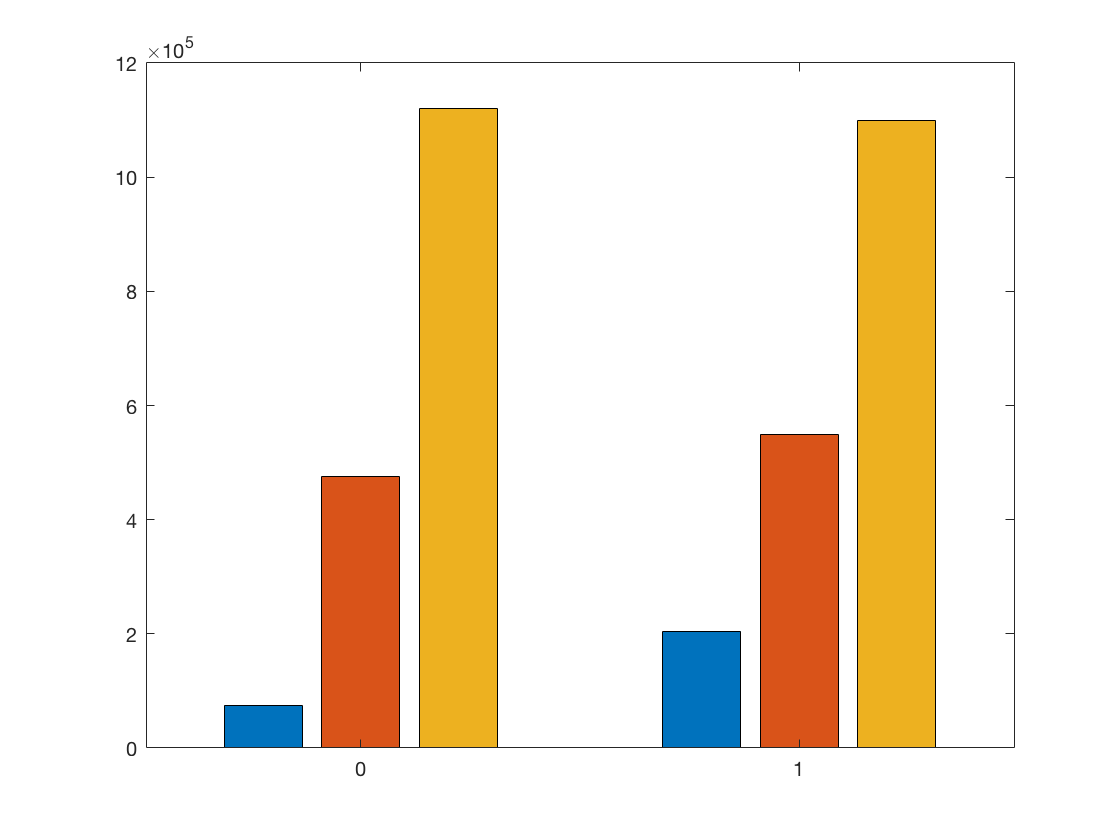

bar(statspricewaterfront)
    xticklabels(WVals)

We can see that the mean price of group 0 (house do not overlook waterfront) is lower than of group 1. So, with the waterfront, the price is higher than without. 

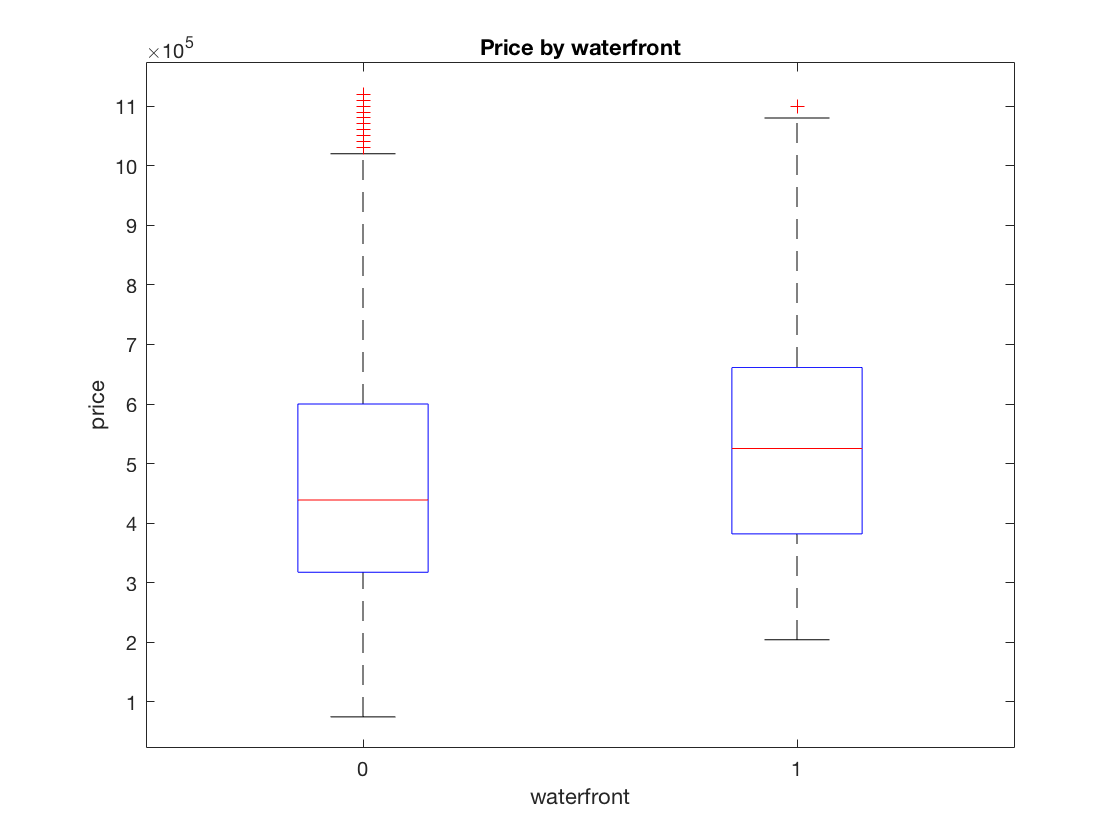

boxplot(a.price,a.waterfront)
title('Price by waterfront')
    xlabel('waterfront')
    ylabel('price')

Same conclusion as above, the overal price of group 1 is higher than group 0. 

                **2. View**

[grpV,VVals] = findgroups(a.view);
statspriceview=splitapply(mystats,a.price,grpV)

statspriceview = 	1.0e+06 *

    0.0750    0.4633    1.1200
    0.2035    0.6016    1.1200
    0.1693    0.5995    1.1200
    0.1540    0.6038    1.1200
    0.1958    0.6032    1.1100


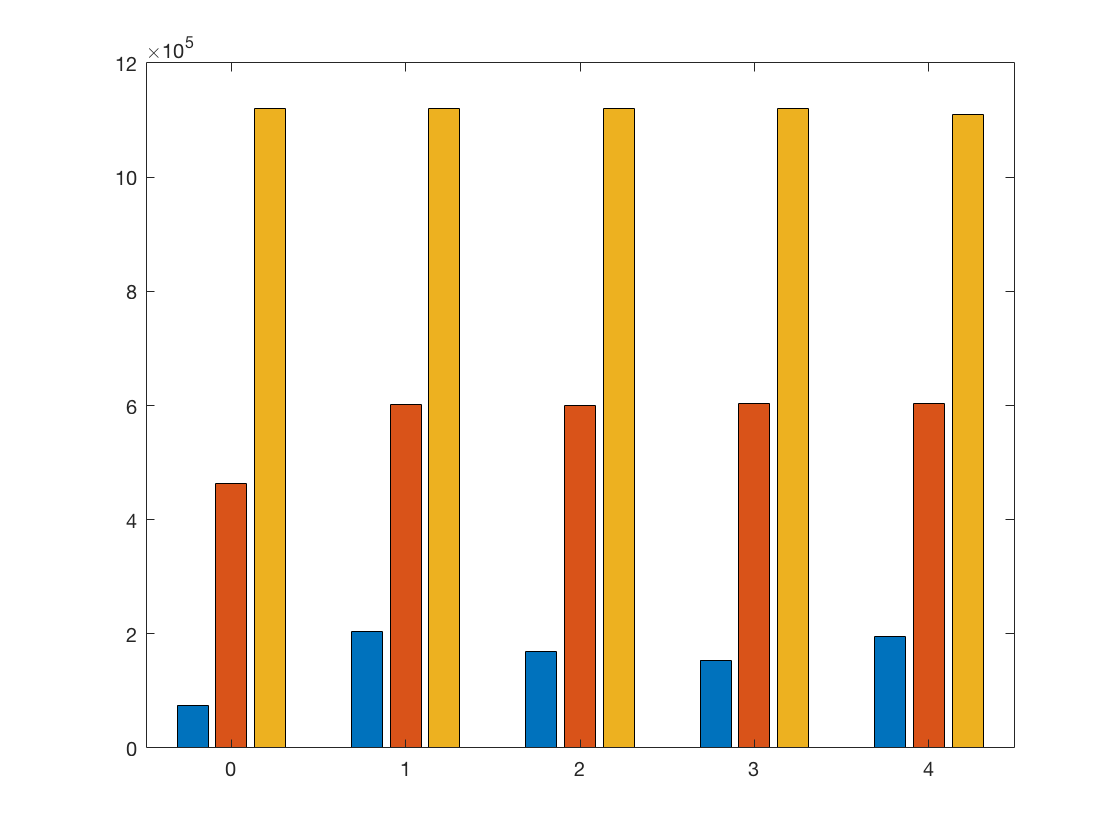

bar(statspriceview)
    xticklabels(VVals)    

The histogram shows us clearly the overal price of each rating in view. 

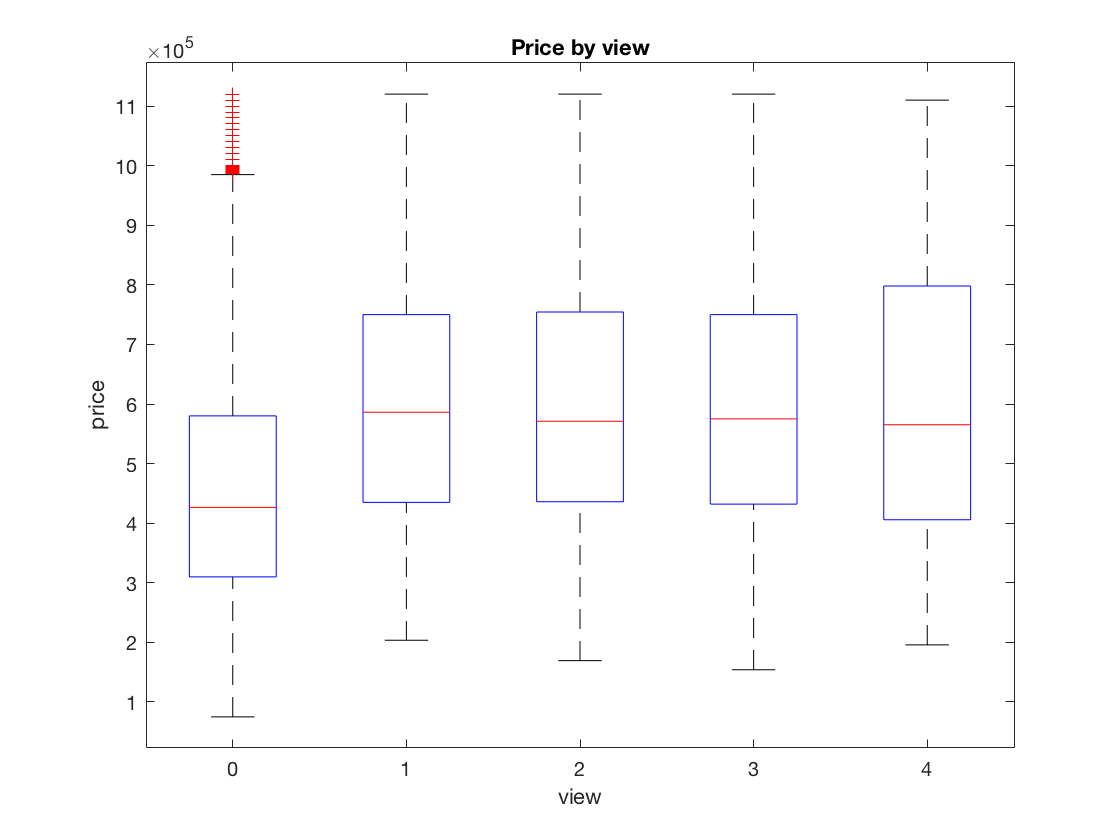

boxplot(a.price,a.view)
title('Price by view')
    xlabel('view')
    ylabel('price')

   **         3. Condition **

[grpC,CVals] = findgroups(a.condition);
statspricecondition=splitapply(mystats,a.price,grpC)

statspricecondition = 	1.0e+06 *

    0.0780    0.2938    0.6580
    0.0800    0.3108    0.9750
    0.0750    0.4793    1.1200
    0.0890    0.4661    1.1200
    0.1100    0.5135    1.1200


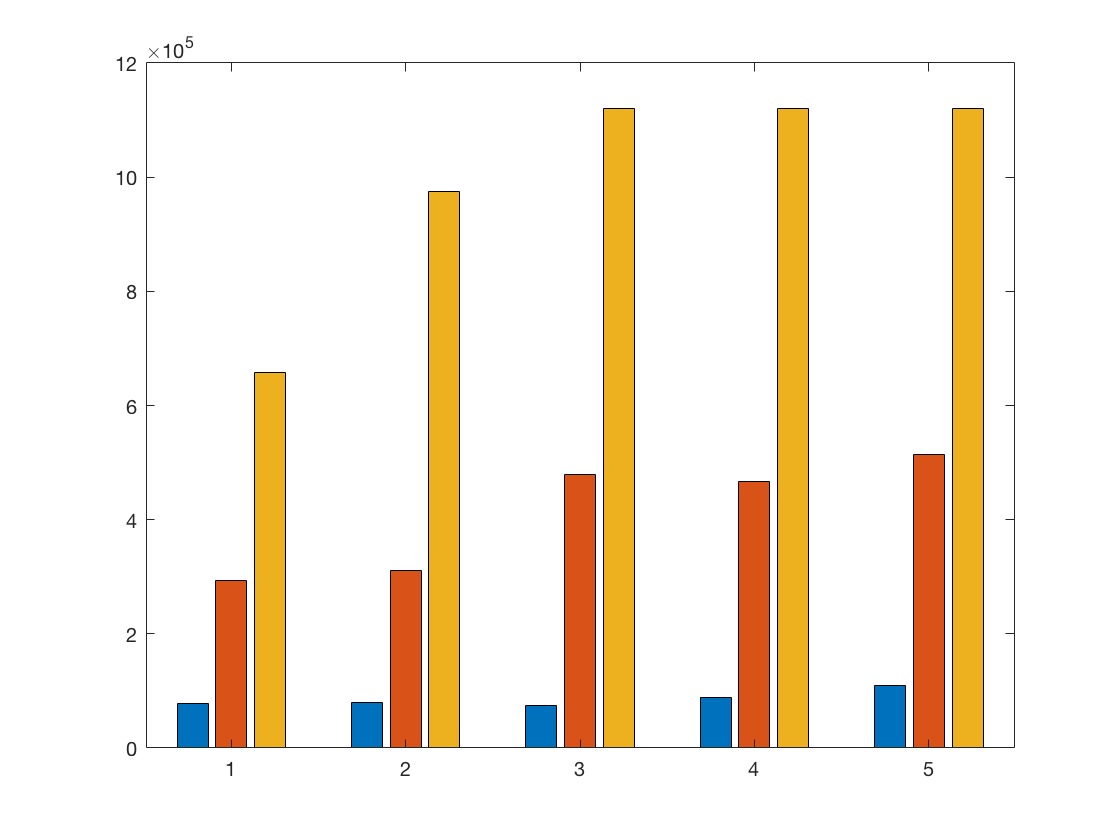

bar(statspricecondition)
    xticklabels(CVals)

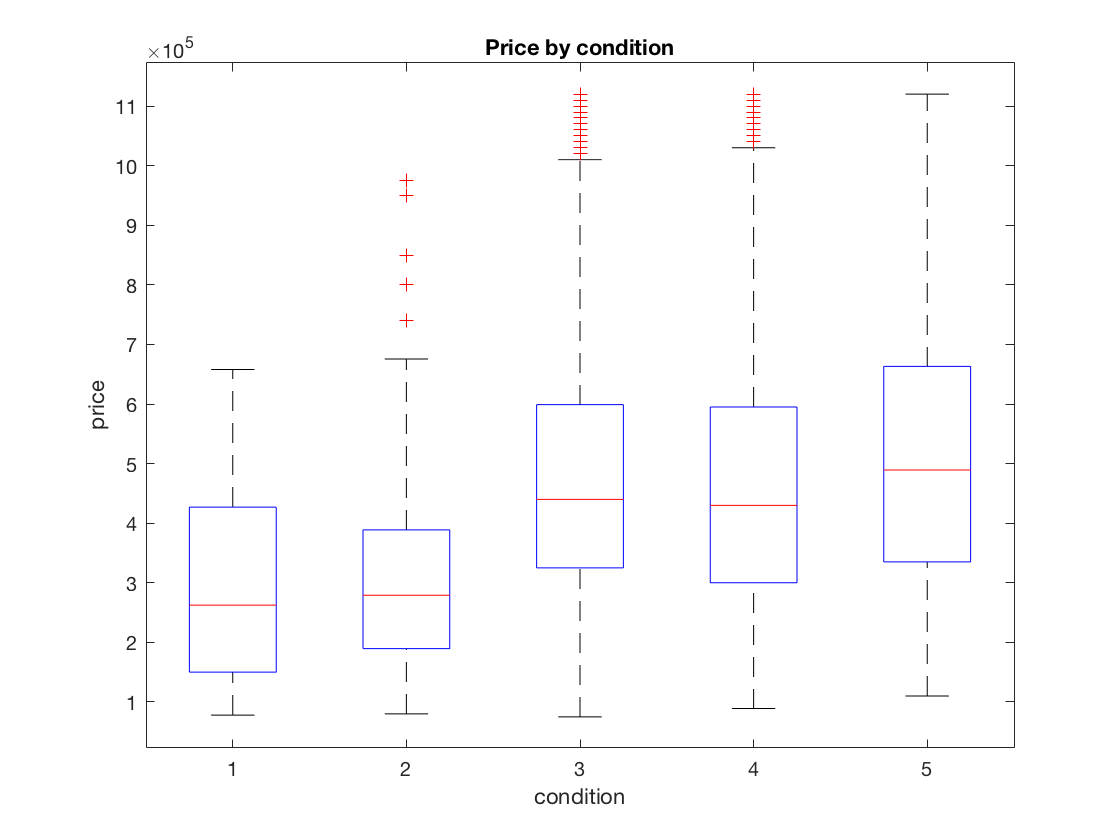

boxplot(a.price,a.condition)
title('Price by condition')
    xlabel('condition')
    ylabel('price')

     **     4. Grade**

[grpG,GVals] = findgroups(a.grade);
statspricegrade=splitapply(mystats,a.price,grpG)

statspricegrade = 	1.0e+06 *

    0.1420    0.1420    0.1420
    0.0750    0.2057    0.2800
    0.0800    0.2144    0.4350
    0.0780    0.2485    0.7950
    0.0820    0.3017    1.0500
    0.0900    0.4013    1.1200
    0.1400    0.5246    1.1200
    0.1729    0.6639    1.1200
    0.1945    0.7054    1.1200
    0.1958    0.6309    1.1200


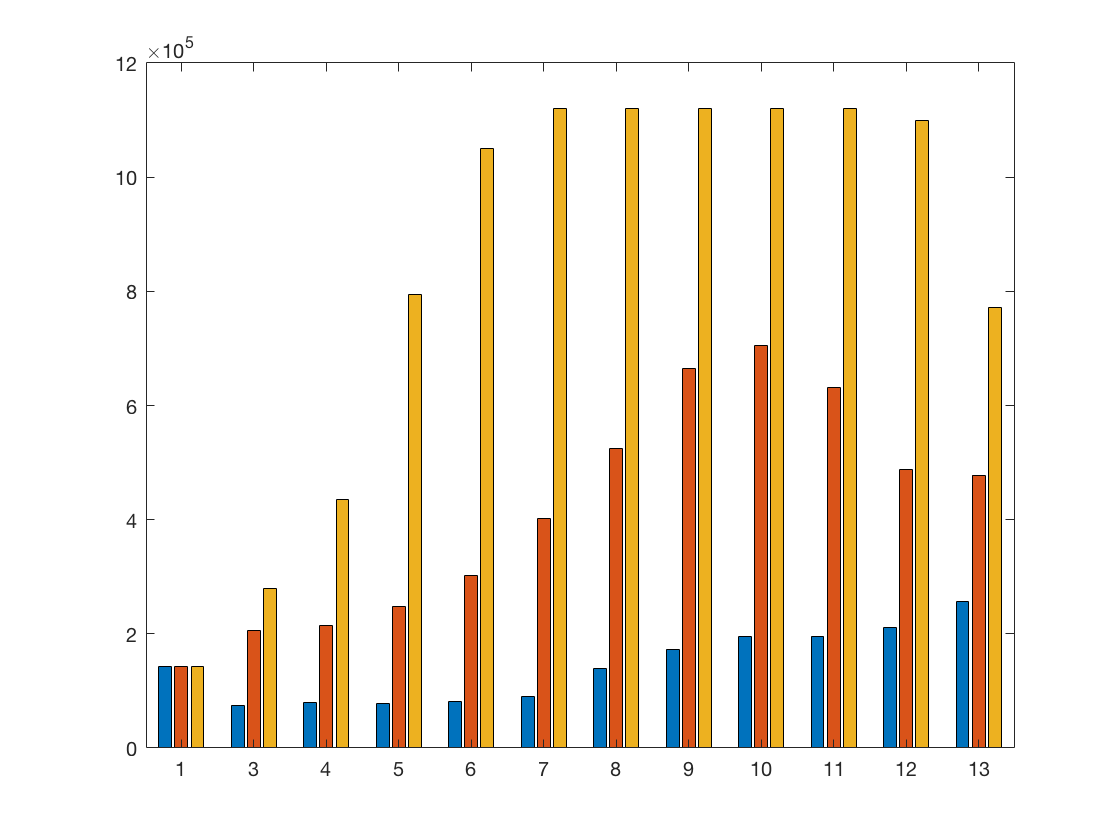

bar(statspricegrade)
    xticklabels(GVals)

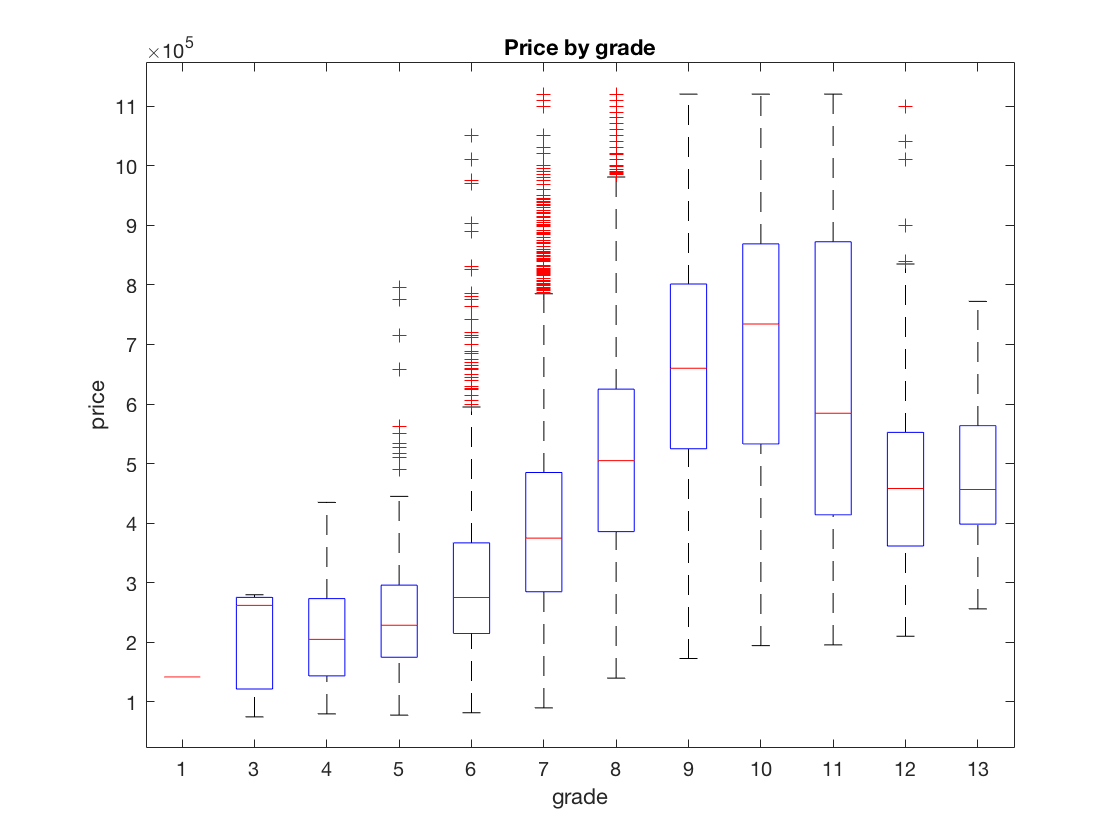

boxplot(a.price,a.grade)
title('Price by grade')
    xlabel('grade')
    ylabel('price')

Next, we analyze 3 variables. A scatter plot will be created to describe the relationship between price, year built and grade. 

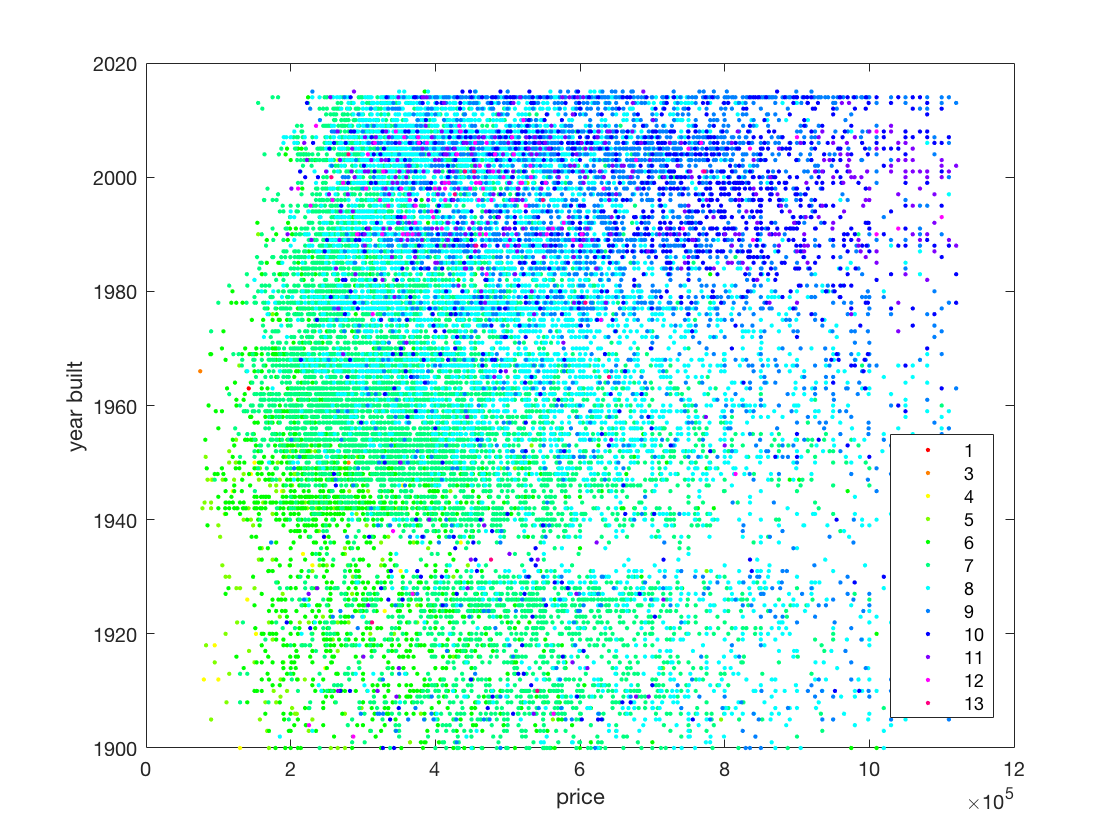

gscatter(a.price,a.yr_built,categorical(a.grade))
    xlabel('price')
    ylabel('year built')

The graph shows us that houses built in recent years tends to have higher grade, while the price spreads evenly no matter in which year the houses are built and their grades. 

# Cross Validation 

We separate the data with 70% is training data and 30% is test data. We set matrix x as predictors and y as target

data = table2array(a);
y=data(:,1); x=data; x(:,1)=[];

rng('default') 
cv = cvpartition(length(data),'holdout',0.30)

cv = Hold-out cross validation partition
   NumObservations: 21613
       NumTestSets: 1
         TrainSize: 15130
          TestSize: 6483

xtrain = x(training(cv),:);
ytrain = y(training(cv),:); 
xtest = x(test(cv),:);
ytest = y(test(cv),:);

# Principal component regression

Principal component analysis of the xtrain. 

[coeff,scoreTrain,~,~,explained,mu] = pca(xtrain)

coeff =     0.0000   -0.0000    0.0004    0.0003   -0.0002    0.0001   -0.0008   -0.0002   -0.0608   -0.4106    0.8679   -0.1977   -0.1858    0.0271    0.0071   -0.0012    0.0026
    0.0000   -0.0000    0.0004    0.0002   -0.0001    0.0001   -0.0018    0.0078    0.0857   -0.1046    0.1633    0.0274    0.8729   -0.4384   -0.0008    0.0011    0.0008
    0.0385   -0.0040    0.6723    0.3998   -0.3454   -0.5171    0.0023   -0.0050   -0.0004    0.0004   -0.0003   -0.0000   -0.0002    0.0001   -0.0000   -0.0000    0.0000
    0.7541   -0.6554   -0.0418   -0.0041    0.0042    0.0010    0.0014    0.0011   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    0.0003   -0.0004   -0.0001   -0.0000   -0.0002    0.0055    0.1149   -0.0714    0.0247   -0.0572    0.4254    0.8923   -0.0119    0.0212   -0.0070
    0.0280   -0.0030    0.5888   -0.5142   -0.2794    0.5568    0.0083   -0.0086   -0.0003    0.0003   -0.0002    0.0001   -0.0002   -0.0

scoreTrain = 	1.0e+04 *

    0.0107    0.0384    0.0541    0.0098   -0.0553    0.0057    0.0049   -0.0015   -0.0001    0.0000   -0.0001   -0.0000    0.0001    0.0000    0.0000   -0.0000    0.0000
   -0.3373   -0.0139   -0.0450    0.0835   -0.0283    0.0083    0.0021    0.0015   -0.0000   -0.0000    0.0001    0.0001    0.0001   -0.0001   -0.0000   -0.0000    0.0000
    0.0604   -0.0261   -0.0343   -0.0313    0.0001   -0.0017   -0.0003    0.0016    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000
   -0.0086   -0.0102   -0.0183   -0.0311    0.0191   -0.0021   -0.0024    0.0023    0.0003   -0.0002    0.0000   -0.0000   -0.0001   -0.0001    0.0000    0.0000    0.0000
   -0.0776    0.0057   -0.0023   -0.0309    0.0381   -0.0026   -0.0070    0.0006   -0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3231    0.0338   -0.1352   -0.0256    0.0212   -0.0035    0.0121    0.0029   -0.0000   -0.0000    0.0000   -0.0000

explained =    84.5145
    9.2185
    4.5699
    0.9163
    0.5830
    0.1848
    0.0106
    0.0025
    0.0000
    0.0000


mu = 	1.0e+04 *

    0.0003    0.0002    0.2003    0.7438    0.0001    0.1713    0.0260    9.8078    0.0048   -0.0122    0.1935    0.7290    0.0000    0.0000    0.0003    0.0008    0.1971


Use graph to illustrate the explained

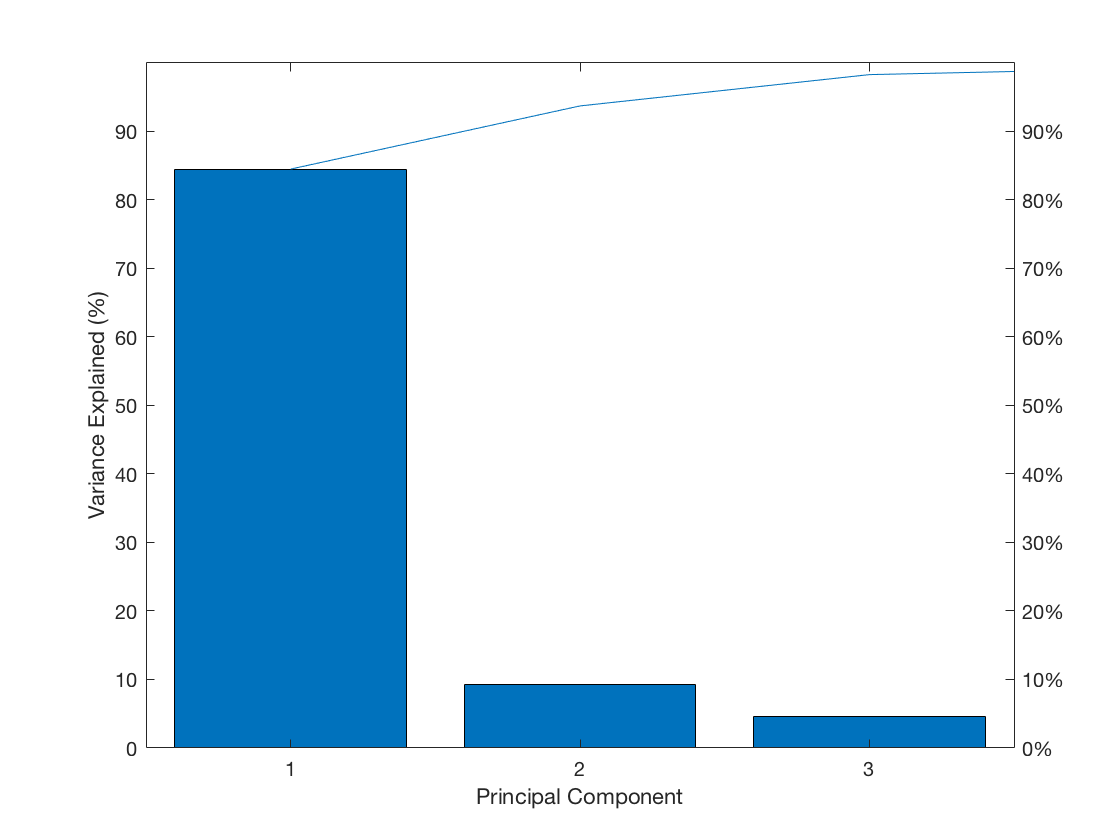

figure()
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained (%)')

Based on the pareto graph, we see that the first 3 components explain 98.3% of variance in Xtrain. 

**Choose the optimal number of pcs by k-fold validation method**

[n,p] = size(x);
PCRmsep = sum(crossval(@pcrsse,x,y,'KFold',7),1) / n

PCRmsep = 	1.0e+10 *

    4.2131    4.2131    4.2136    2.8083    2.7210    2.7041    2.6999    2.6560    2.5768    2.3794    2.3436


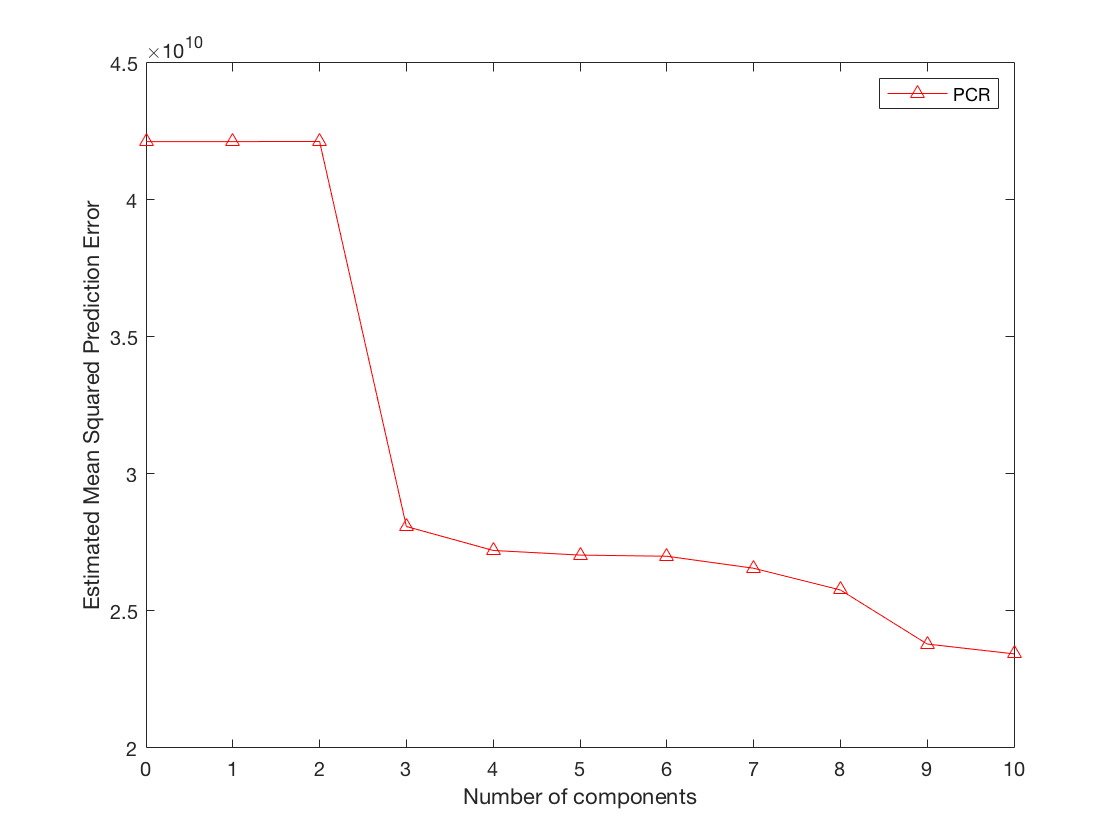

plot(0:10,PCRmsep,'r-^');
xlabel('Number of components');
ylabel('Estimated Mean Squared Prediction Error');
legend('PCR');

Based on the graph, 3 pcs is the best choice because from 2PCs to 3PCS, Estimated Mean Squared Prediction Error (EMSPR) improved significantly. The more number of PCs, the less EMSPR though the difference is little after 3 PCs. Now, to make a complete anlysis, we make models with all possible components (4 components, 5 components, 6 components,...10 components), and choose the model (number of components) that minimizes MSE in test data.

## PCR with 2 PCs: 

scoreTrain2comp = scoreTrain(:,1:2); 
mdl_2pcs = fitlm(scoreTrain2comp,ytrain)

mdl_2pcs = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE        tStat      pValue 
                   _________    _______    ________    _______

    (Intercept)    4.772e+05     1666.6      286.32          0
    x1               0.35057    0.37089     0.94519    0.34458
    x2              -0.16648      1.123    -0.14824    0.88215


Number of observations: 15130, Error degrees of freedom: 15127
Root Mean Squared Error: 2.05e+05
R-squared: 6.05e-05,  Adjusted R-Squared: -7.17e-05
F-statistic vs. constant model: 0.458, p-value = 0.633

scoreTest2comp = (xtest-mu)*coeff(:,1:2);
YTest_predicted_2PCs = predict(mdl_2pcs,scoreTest2comp);

Let's graph the predicted value and the real value to compare

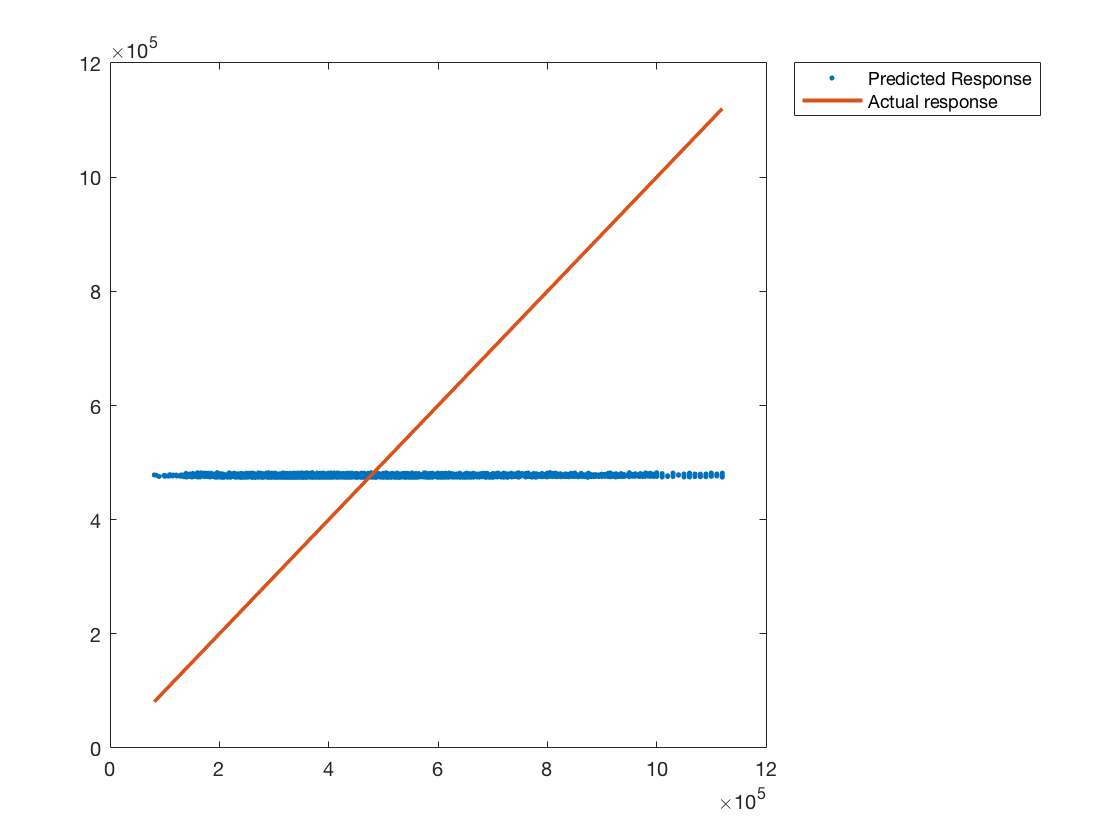

figure
plot(ytest,YTest_predicted_2PCs,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

## PCR with 3 PCs: 

scoreTrain3comp = scoreTrain(:,1:3); 
mdl_3pcs = fitlm(scoreTrain3comp,ytrain)

mdl_3pcs = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE        tStat      pValue 
                   _________    _______    ________    _______

    (Intercept)    4.772e+05       1360      350.89          0
    x1               0.35057    0.30265      1.1583    0.24674
    x2              -0.16648    0.91637    -0.18167    0.85584
    x3                113.41     1.3015      87.135          0


Number of observations: 15130, Error degrees of freedom: 15126
Root Mean Squared Error: 1.67e+05
R-squared: 0.334,  Adjusted R-Squared: 0.334
F-statistic vs. constant model: 2.53e+03, p-value = 0

scoreTest3comp = (xtest-mu)*coeff(:,1:3);
YTest_predicted_3PCs = predict(mdl_3pcs,scoreTest3comp);

Let's graph the predicted value and the real value to compare

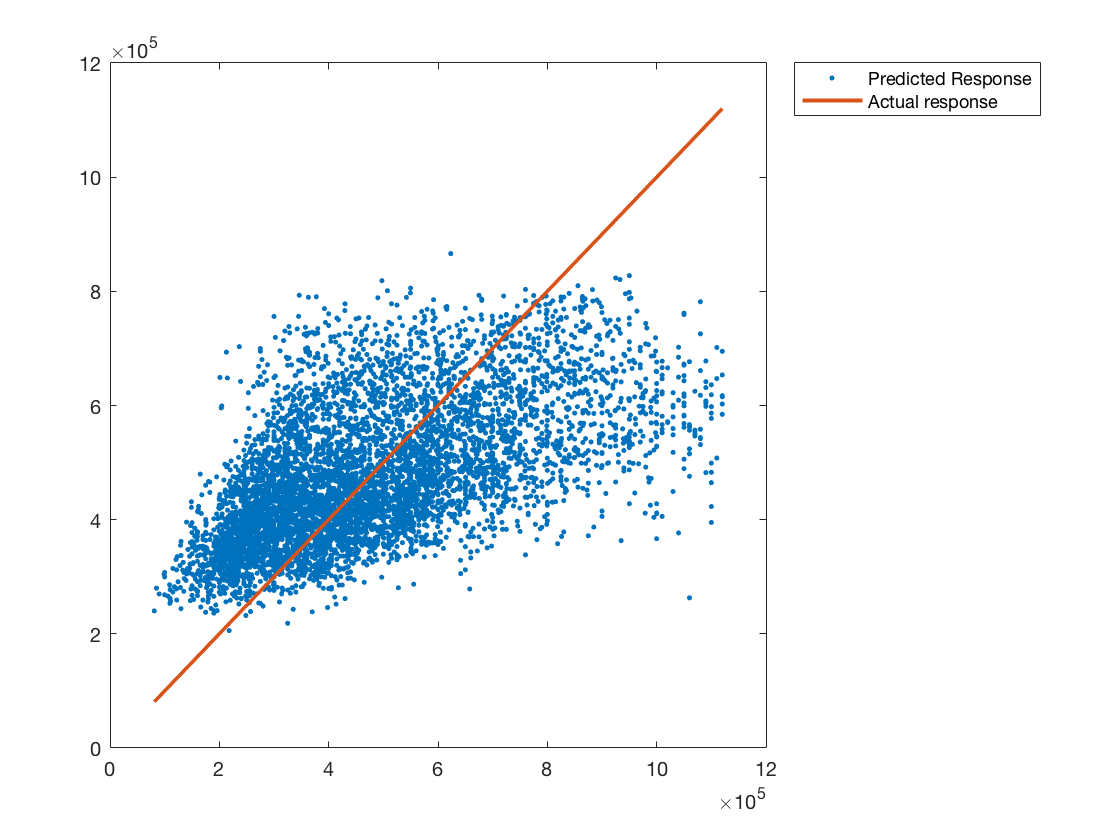

figure
plot(ytest,YTest_predicted_3PCs,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

## PCR with 4 PCs: 

scoreTrain4comp = scoreTrain(:,1:4); 
mdl_4pcs = fitlm(scoreTrain4comp,ytrain)

mdl_4pcs = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)    4.772e+05     1338.1      356.63             0
    x1               0.35057    0.29778      1.1773        0.2391
    x2              -0.16648    0.90162    -0.18464       0.85351
    x3                113.41     1.2806      88.561             0
    x4                63.942     2.8598      22.359    5.721e-109


Number of observations: 15130, Error degrees of freedom: 15125
Root Mean Squared Error: 1.65e+05
R-squared: 0.356,  Adjusted R-Squared: 0.355
F-statistic vs. constant model: 2.09e+03, p-value = 0

scoreTest4comp = (xtest-mu)*coeff(:,1:4);
YTest_predicted_4PCs = predict(mdl_4pcs,scoreTest4comp); 

Let's graph the predicted value and the real value to compare

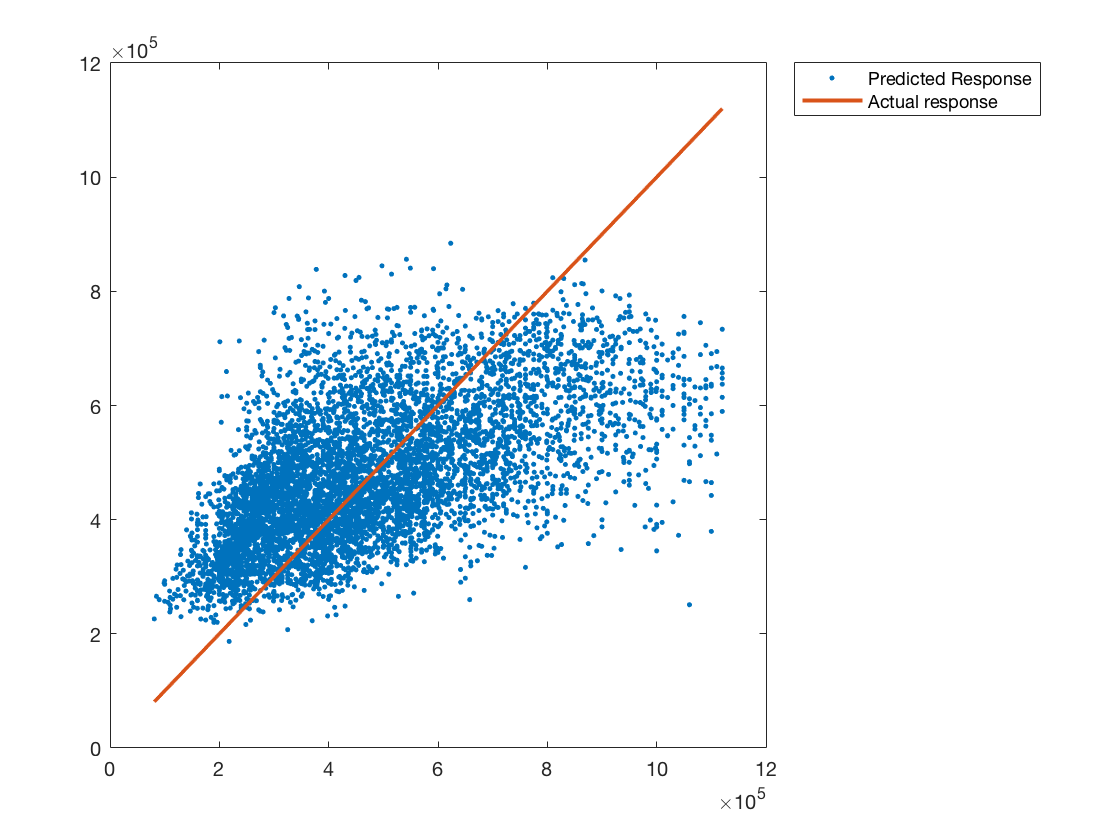

figure
plot(ytest,YTest_predicted_4PCs,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

## PCR with 5 PCs: 

scoreTrain5comp = scoreTrain(:,1:5); 
mdl_5pcs = fitlm(scoreTrain5comp,ytrain)

mdl_5pcs = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
                   Estimate       SE        tStat        pValue   
                   _________    _______    ________    ___________

    (Intercept)    4.772e+05       1334      357.73              0
    x1               0.35057    0.29686      1.1809        0.23765
    x2              -0.16648    0.89885    -0.18521        0.85306
    x3                113.41     1.2766      88.834              0
    x4                63.942      2.851      22.428    1.2765e-109
    x5                34.766     3.5744      9.7265     2.7016e-22


Number of observations: 15130, Error degrees of freedom: 15124
Root Mean Squared Error: 1.64e+05
R-squared: 0.36,  Adjusted R-S

scoreTest5comp = (xtest-mu)*coeff(:,1:5);
YTest_predicted_5PCs = predict(mdl_5pcs,scoreTest5comp); 

Let's graph the predicted value and the real value to compare

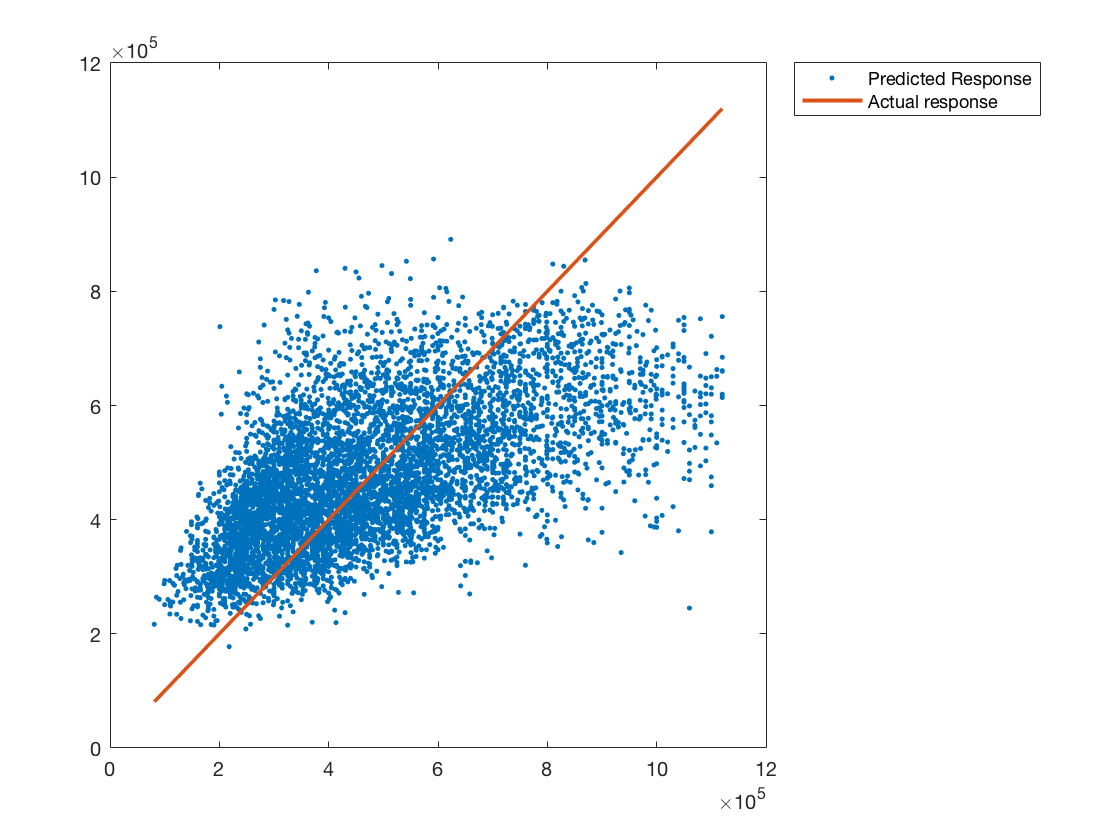

figure
plot(ytest,YTest_predicted_5PCs,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

## PCR with 6 PCs: 

scoreTrain6comp = scoreTrain(:,1:6); 
mdl_6pcs = fitlm(scoreTrain6comp,ytrain)

mdl_6pcs = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                   Estimate       SE        tStat        pValue   
                   _________    _______    ________    ___________

    (Intercept)    4.772e+05     1333.1      357.97              0
    x1               0.35057    0.29666      1.1817        0.23733
    x2              -0.16648    0.89824    -0.18534        0.85297
    x3                113.41     1.2758      88.895              0
    x4                63.942      2.849      22.443    9.1792e-110
    x5                34.766      3.572      9.7331     2.5335e-22
    x6               -29.394     6.3441     -4.6332     3.6308e-06


Number of observations: 15130, Error d

scoreTest6comp = (xtest-mu)*coeff(:,1:6);
YTest_predicted_6PCs = predict(mdl_6pcs,scoreTest6comp); 

Let's graph the predicted value and the real value to compare

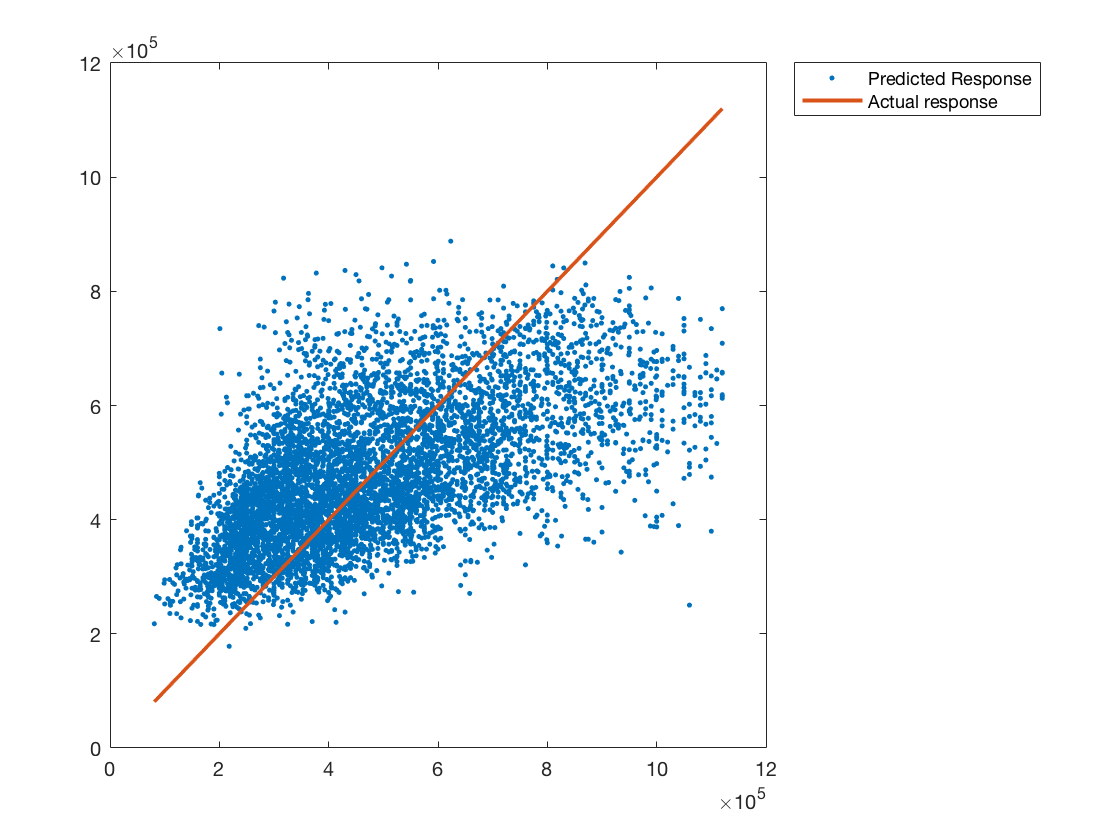

figure
plot(ytest,YTest_predicted_6PCs,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

## PCR with 7 PCs: 

scoreTrain7comp = scoreTrain(:,1:7); 
mdl_7pcs = fitlm(scoreTrain7comp,ytrain)

mdl_7pcs = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7

Estimated Coefficients:
                   Estimate       SE        tStat        pValue   
                   _________    _______    ________    ___________

    (Intercept)    4.772e+05     1322.4      360.86              0
    x1               0.35057    0.29429      1.1912        0.23357
    x2              -0.16648    0.89106    -0.18683        0.85179
    x3                113.41     1.2656      89.611              0
    x4                63.942     2.8263      22.624    1.7631e-111
    x5                34.766     3.5434      9.8116     1.1732e-22
    x6               -29.394     6.2934     -4.6705     3.0299e-06
    x7            

scoreTest7comp = (xtest-mu)*coeff(:,1:7);
YTest_predicted_7PCs = predict(mdl_7pcs,scoreTest7comp); 

Let's graph the predicted value and the real value to compare

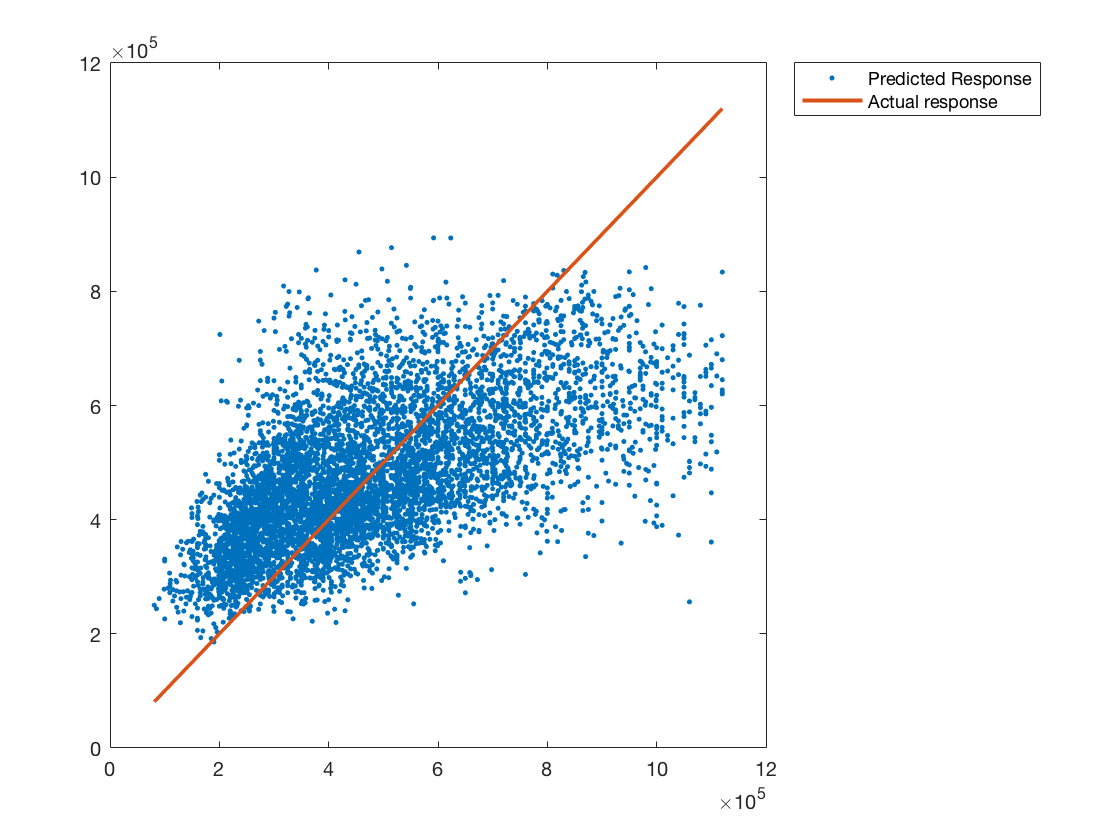

figure
plot(ytest,YTest_predicted_7PCs,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

## PCR with 8 PCs: 

scoreTrain8comp = scoreTrain(:,1:8); 
mdl_8pcs = fitlm(scoreTrain8comp,ytrain)

mdl_8pcs = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8

Estimated Coefficients:
                   Estimate       SE        tStat        pValue   
                   _________    _______    ________    ___________

    (Intercept)    4.772e+05       1303      366.23              0
    x1               0.35057    0.28997       1.209        0.22669
    x2              -0.16648    0.87798    -0.18961        0.84961
    x3                113.41      1.247      90.945              0
    x4                63.942     2.7848      22.961    1.0392e-114
    x5                34.766     3.4914      9.9576     2.7546e-23
    x6               -29.394     6.2011     -4.7401     2.1558e-06
    x7         

scoreTest8comp = (xtest-mu)*coeff(:,1:8);
YTest_predicted_8PCs = predict(mdl_8pcs,scoreTest8comp); 

Let's graph the predicted value and the real value to compare

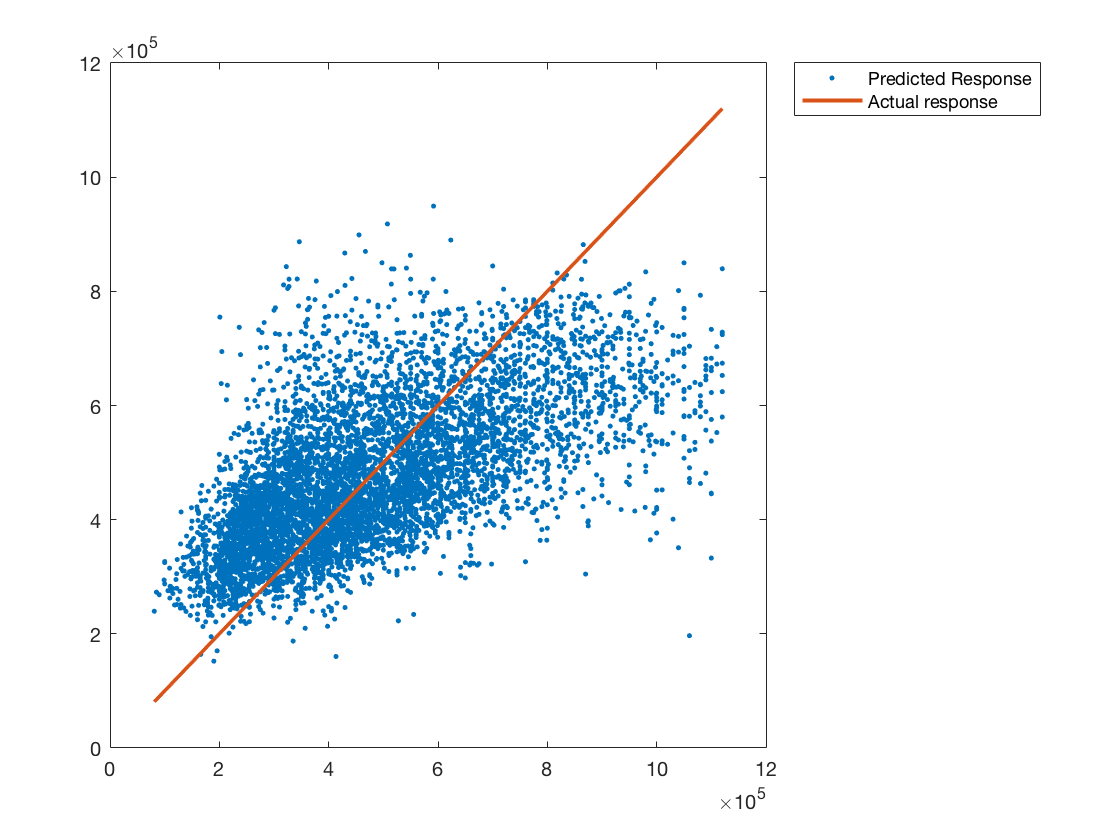

figure
plot(ytest,YTest_predicted_8PCs,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

## PCR with 9 PCs: 

scoreTrain9comp = scoreTrain(:,1:9); 
mdl_9pcs = fitlm(scoreTrain9comp,ytrain)

mdl_9pcs = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   _________    _______    _______    ___________

    (Intercept)    4.772e+05     1252.8     380.89              0
    x1               0.35057    0.27881     1.2574        0.20864
    x2              -0.16648    0.84419    -0.1972        0.84367
    x3                113.41      1.199     94.586              0
    x4                63.942     2.6776      23.88    9.5511e-124
    x5                34.766      3.357     10.356     4.7564e-25
    x6               -29.394     5.9624    -4.9298     8.3185e-07
    x7           

scoreTest9comp = (xtest-mu)*coeff(:,1:9);
YTest_predicted_9PCs = predict(mdl_9pcs,scoreTest9comp); 

Let's graph the predicted value and the real value to compare

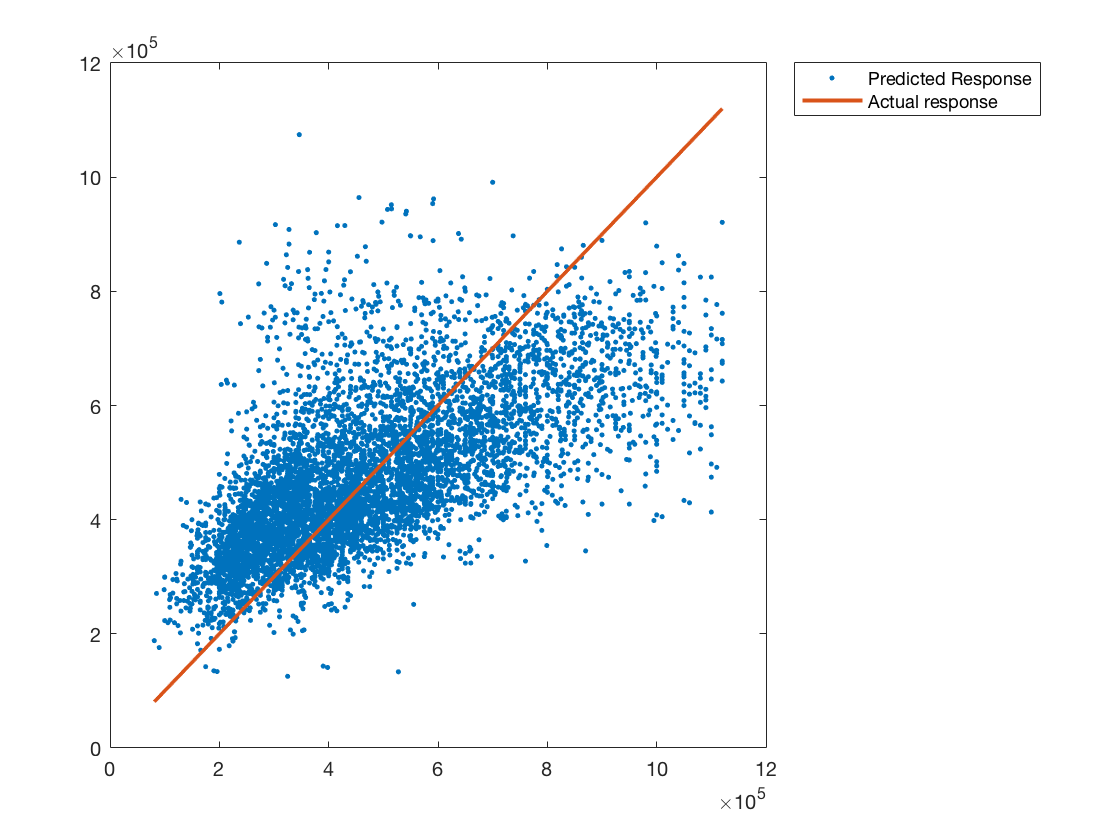

figure
plot(ytest,YTest_predicted_9PCs,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

## PCR with 10 PCs: 

scoreTrain10comp = scoreTrain(:,1:10); 
mdl_10pcs = fitlm(scoreTrain10comp,ytrain)

mdl_10pcs = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10

Estimated Coefficients:
                   Estimate       SE        tStat        pValue   
                   _________    _______    ________    ___________

    (Intercept)    4.772e+05     1243.2      383.86              0
    x1               0.35057    0.27665      1.2672        0.20511
    x2              -0.16648    0.83767    -0.19874        0.84247
    x3                113.41     1.1897      95.322              0
    x4                63.942     2.6569      24.066    1.2927e-125
    x5                34.766     3.3311      10.437      2.053e-25
    x6               -29.394     5.9163     -4.9682     6.8316e-07
    x7    

scoreTest10comp = (xtest-mu)*coeff(:,1:10);
YTest_predicted_10PCs = predict(mdl_10pcs,scoreTest10comp); 

Let's graph the predicted value and the real value to compare

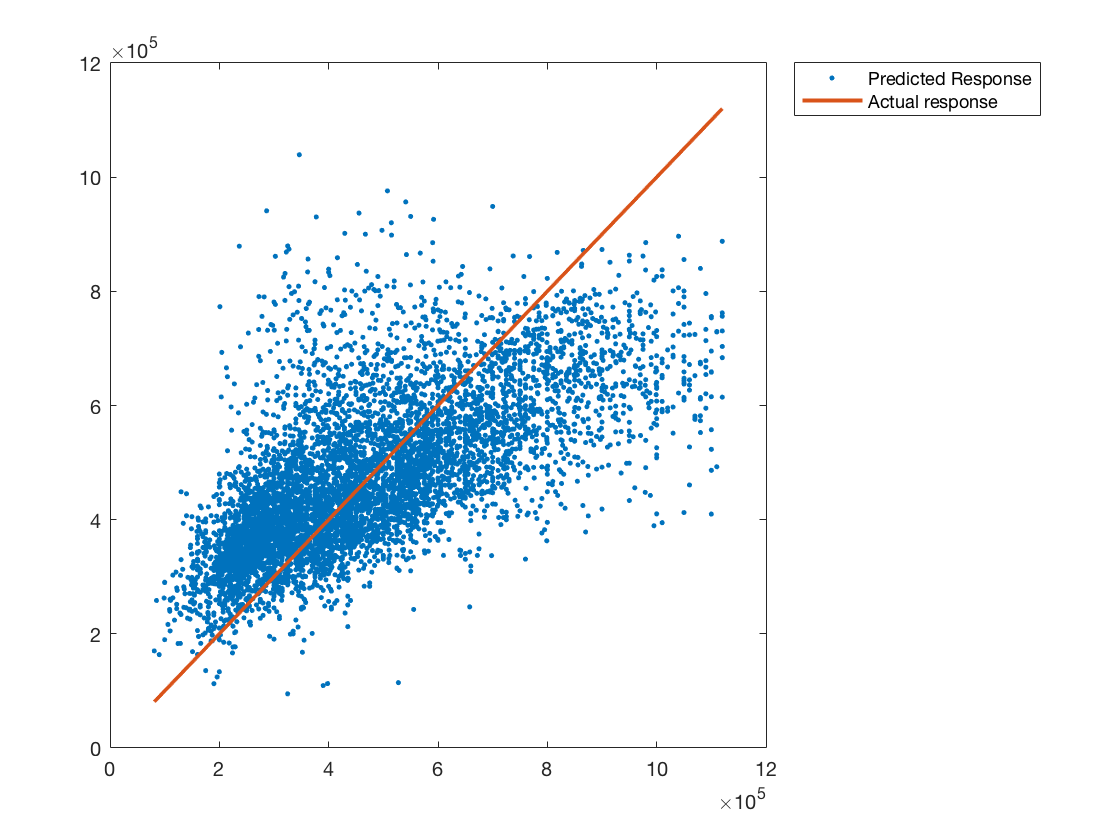

figure
plot(ytest,YTest_predicted_10PCs,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

Evaluate which models predict most correctly. 

MSEpcr2comp = immse(ytest,YTest_predicted_2PCs)

MSEpcr2comp = 4.2374e+10

MSEpcr3comp = immse(ytest,YTest_predicted_3PCs)

MSEpcr3comp = 2.8270e+10

MSEpcr4comp = immse(ytest,YTest_predicted_4PCs)

MSEpcr4comp = 2.7456e+10

MSEpcr5comp = immse(ytest,YTest_predicted_5PCs)

MSEpcr5comp = 2.7283e+10

MSEpcr6comp = immse(ytest,YTest_predicted_6PCs)

MSEpcr6comp = 2.7198e+10

MSEpcr7comp = immse(ytest,YTest_predicted_7PCs)

MSEpcr7comp = 2.6726e+10

MSEpcr8comp = immse(ytest,YTest_predicted_8PCs)

MSEpcr8comp = 2.5885e+10

MSEpcr9comp = immse(ytest,YTest_predicted_9PCs)

MSEpcr9comp = 2.3856e+10

MSEpcr10comp = immse(ytest,YTest_predicted_10PCs)

MSEpcr10comp = 2.3404e+10

The objective is to minimise MSE and the model with 10pcs has smallest MSE among all. Therefore, at this point, PCR model  with 10 PCs predicts most correctly. 

# LINEAR REGRESSION 

## Default linear regression model

mdl=fitlm(xtrain,ytrain,'linear')

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17

Estimated Coefficients:
                    Estimate          SE         tStat        pValue   
                   ___________    __________    ________    ___________

    (Intercept)    -4.5144e+06    2.4086e+06     -1.8743       0.060912
    x1                 -8822.8        1746.6     -5.0515     4.4343e-07
    x2                   19754        2680.4      7.3698     1.7977e-13
    x3                  81.564        3.3613      24.266    1.2335e-127
    x4                  -3.672       0.53956     -6.8055     1.0449e-11
    x5                  4837.8        3150.4      1.5356        0.12465
    x6         

Ypredicted_test= mdl.predict(xtest);

Let's graph the predicted value and the real value to compare

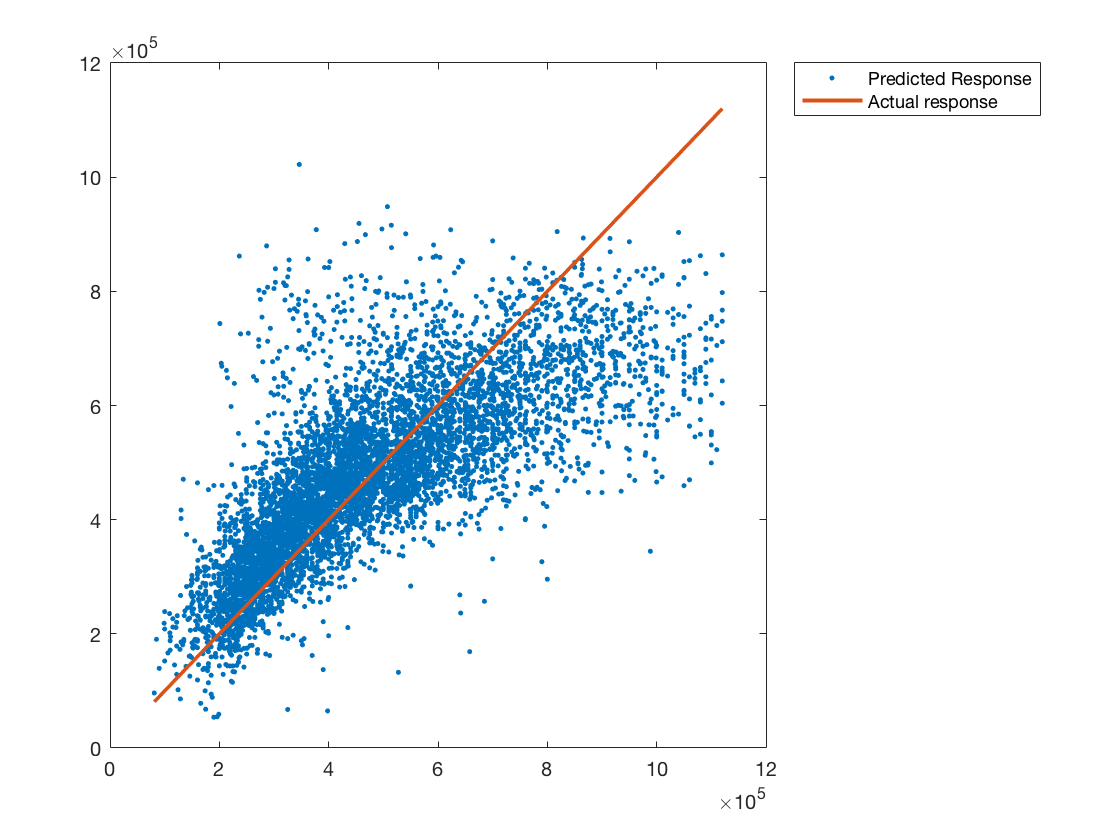

figure
plot(ytest,Ypredicted_test,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

## Adjusted model

Correlation of all attributes.  

corr(data)

ans =     1.0000    0.2750    0.4059    0.5608   -0.0013    0.2623    0.4510    0.1856   -0.0185    0.4225    0.0908    0.4867    0.0001    0.0310    0.1862    0.0355    0.5354    0.0597
    0.2750    1.0000    0.4593    0.5565    0.2015    0.1734    0.4534    0.2319   -0.1705   -0.0243    0.1819    0.3930    0.1935   -0.0040    0.0760    0.0180    0.3573    0.1759
    0.4059    0.4593    1.0000    0.6723    0.0062    0.4952    0.5949    0.1940   -0.2140    0.0062    0.2596    0.5020    0.0053    0.0296    0.1297   -0.1246    0.5863    0.5282
    0.5608    0.5565    0.6723    1.0000    0.2087    0.3397    0.7762    0.2987   -0.1949    0.0408    0.2701    0.6783    0.1953    0.0474    0.1948   -0.0528    0.6499    0.3226
   -0.0013    0.2015    0.0062    0.2087    1.0000   -0.2904    0.1649    0.0673   -0.2470   -0.1178    0.2141    0.2449    0.8017    0.0615    0.1029    0.1043    0.1155   -0.0240
    0.2623    0.1734    0.4952    0.3397   -0.2904    1.0000    0.5214   -0.2580   -0.059

Focus on the price variable, sqft_lot and sqft_lot15 have no effect on the price. 

Construct another model without those variables

xtrain2=xtrain; xtrain2(:,[4 12])=[]; 
xtest2=xtest; xtest2(:,[4 12])=[];

mdl2=fitlm(xtrain2,ytrain,'linear')

mdl2 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)    -1.2395e+07    2.3886e+06    -5.1891     2.1403e-07
    x1                  -12146        1753.1    -6.9285     4.4257e-12
    x2                   24019        2695.3     8.9113     5.6094e-19
    x3                  78.351        3.3883     23.124    2.7345e-116
    x4                   25976        2933.4     8.8553     9.2609e-19
    x5                  5.0327        3.5769      1.407        0.15944
    x6                  1.54

Ypredicted_test2= mdl2.predict(xtest2);

Let's graph the predicted value and the real value to compare

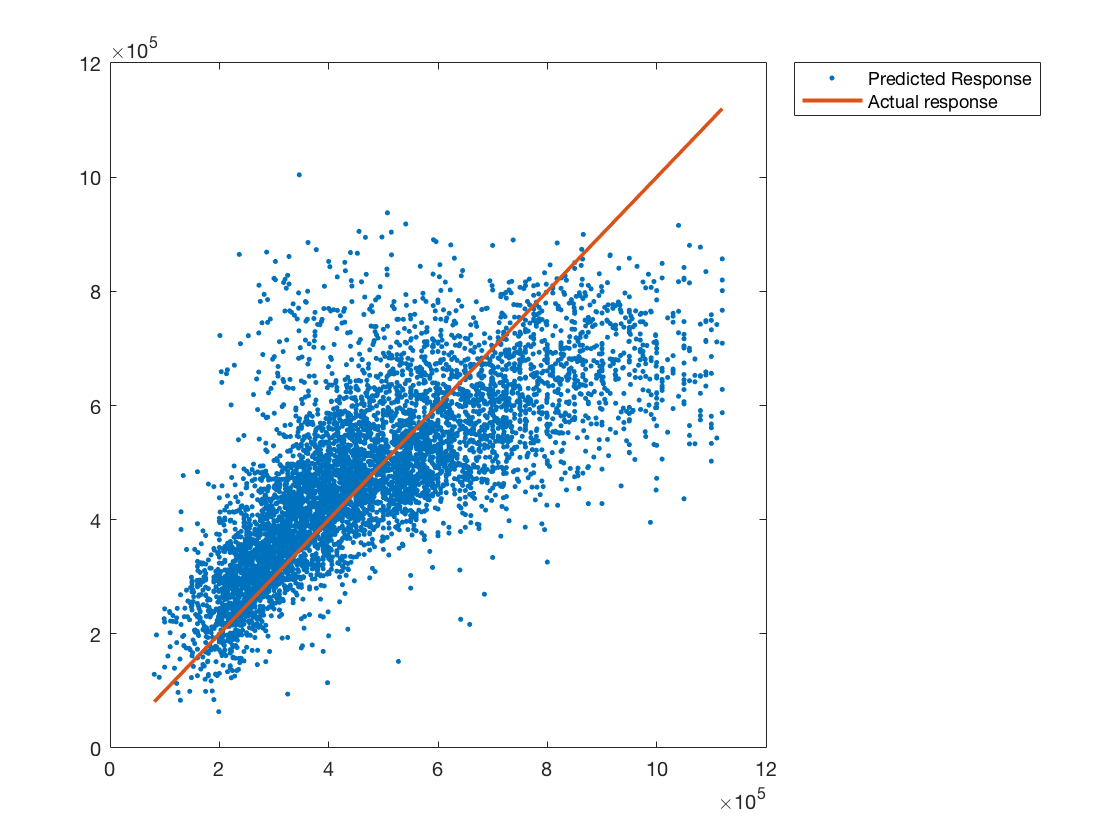

figure
plot(ytest,Ypredicted_test2,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

## Step-Adjusted Model

Improve the model by adding or removing variables using step. 

mdl3 = step(mdl2,'NSteps',10)

1. Adding x12:x14, FStat = 668.3027, pValue = 3.127385e-144
2. Adding x5:x15, FStat = 135.6528, pValue = 3.230752e-31
3. Adding x10:x14, FStat = 124.9557, pValue = 6.756337e-29
4. Adding x9:x10, FStat = 115.8617, pValue = 6.380843e-27
5. Adding x4:x7, FStat = 90.485, pValue = 2.13942e-21
6. Adding x12:x15, FStat = 69.2787, pValue = 9.27409e-17
7. Adding x8:x11, FStat = 56.0156, pValue = 7.58604e-14
8. Adding x3:x8, FStat = 42.5463, pValue = 7.12244e-11
9. Adding x3:x10, FStat = 38.5646, pValue = 5.43583e-10
10. Adding x6:x9, FStat = 21.2026, pValue = 4.16567e-06


mdl3 = Linear regression model:
    y ~ 1 + x1 + x2 + x13 + x3*x8 + x3*x10 + x4*x7 + x5*x15 + x6*x9 + x8*x11 + x9*x10 + x10*x14 + x12*x14 + x12*x15

Estimated Coefficients:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)     1.7139e+07    7.2645e+06     2.3593       0.018323
    x1                  -10514        1690.9    -6.2181     5.1638e-10
    x2                   21594        2618.5     8.2464     1.7652e-16
    x3                 -3314.7        543.25    -6.1016     1.0758e-09
    x4             -4.2045e+07    4.2102e+06    -9.9866     2.0613e-23
    x5                 -1586.4        130.07    -12.197     4.6849e-34
    x6      

Ypredicted_test3= mdl3.predict(xtest2);

Let's graph the predicted value and the real value to compare

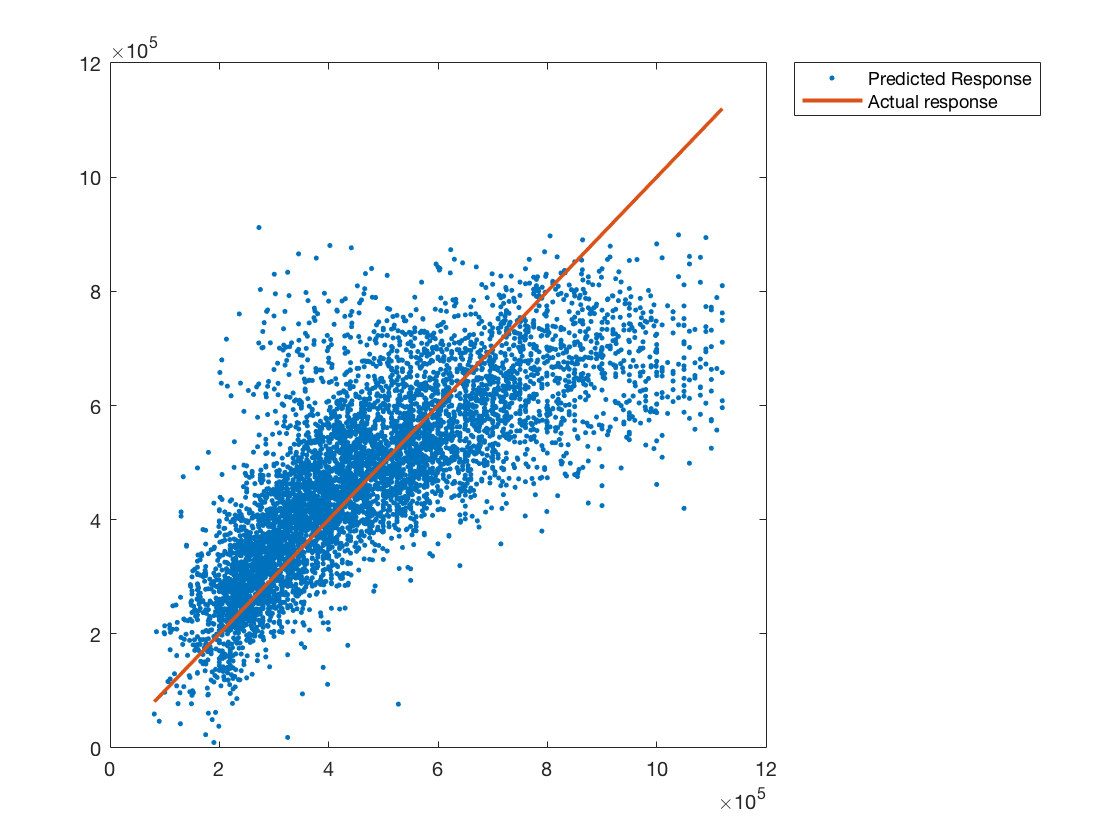

figure
plot(ytest,Ypredicted_test3,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

Evaluate models 

MSEtest = immse(ytest,Ypredicted_test)

MSEtest = 1.8732e+10

RMSEtest = sqrt(MSEtest)

RMSEtest = 1.3687e+05

MSEtest2 = immse(ytest,Ypredicted_test2)

MSEtest2 = 1.9044e+10

RMSEtest2 = sqrt(MSEtest2)

RMSEtest2 = 1.3800e+05

MSEtest3 = immse(ytest,Ypredicted_test3)

MSEtest3 = 1.7542e+10

RMSEtest3 = sqrt(MSEtest3)

RMSEtest3 = 1.3245e+05

RMSEtest3 has smallest value. Therefore, step-adjusted model mdl3 predicts most correctly among 3. 

# REGRESSION DECISION TREE 

mdl_rtree=fitrtree(xtrain,ytrain)

mdl_rtree =   RegressionTree
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 15130


  Properties, Methods


y_rtree=predict(mdl_rtree,xtest);
MSEtree=immse(ytest,y_rtree)

MSEtree = 1.8692e+10

Let's graph the predicted value and the real value to compare

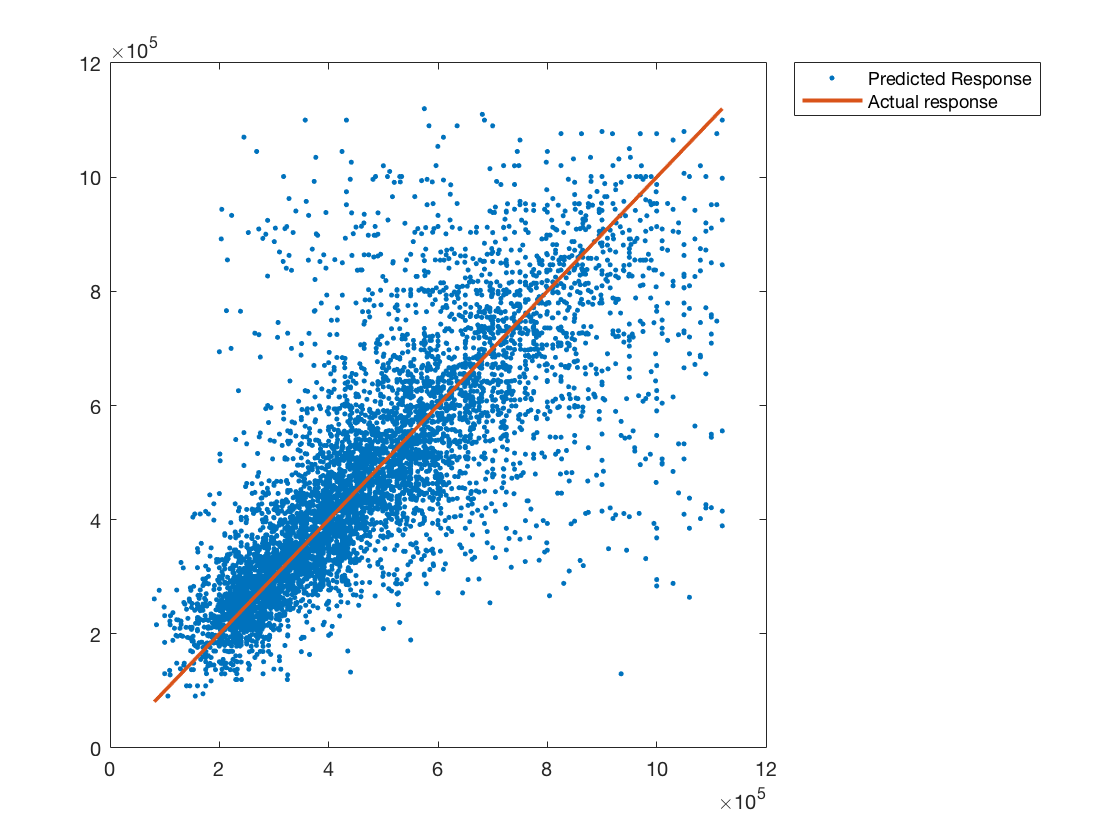

figure
plot(ytest,y_rtree,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

# REGRESSION SVM 

mdl_rsvm=fitrsvm(xtrain,ytrain,'Standardize',true)

mdl_rsvm =   RegressionSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
                    Alpha: [13758×1 double]
                     Bias: 4.3985e+05
         KernelParameters: [1×1 struct]
                       Mu: [3.3511 2.0591 2.0030e+03 7.4376e+03 1.4917 1.7131e+03 259.7236 9.8078e+04 47.5602 -122.2187 1.9351e+03 7.2897e+03 0.0072 0.2346 3.4109 7.6566 1.9710e+03]
                    Sigma: [0.7942 0.6792 766.1170 3.5257e+03 0.5377 690.5116 383.8732 53.5719 0.1383 0.1311 593.5382 3.1458e+03 0.0846 0.7676 0.6526 1.1738 29.4138]
          NumObservations: 15130
           BoxConstraints: [15130×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [15130×1 logical]
                   Solver: 'SMO'


  Properties, Methods


mdl_rsvm.ConvergenceInfo.Converged %check whether the model converges or not

ans = logical
   1


y_rsvm=predict(mdl_rsvm,xtest);
MSEsvm=immse(ytest,y_rsvm)

MSEsvm = 3.7268e+10

Let's graph the predicted value and the real value to compare

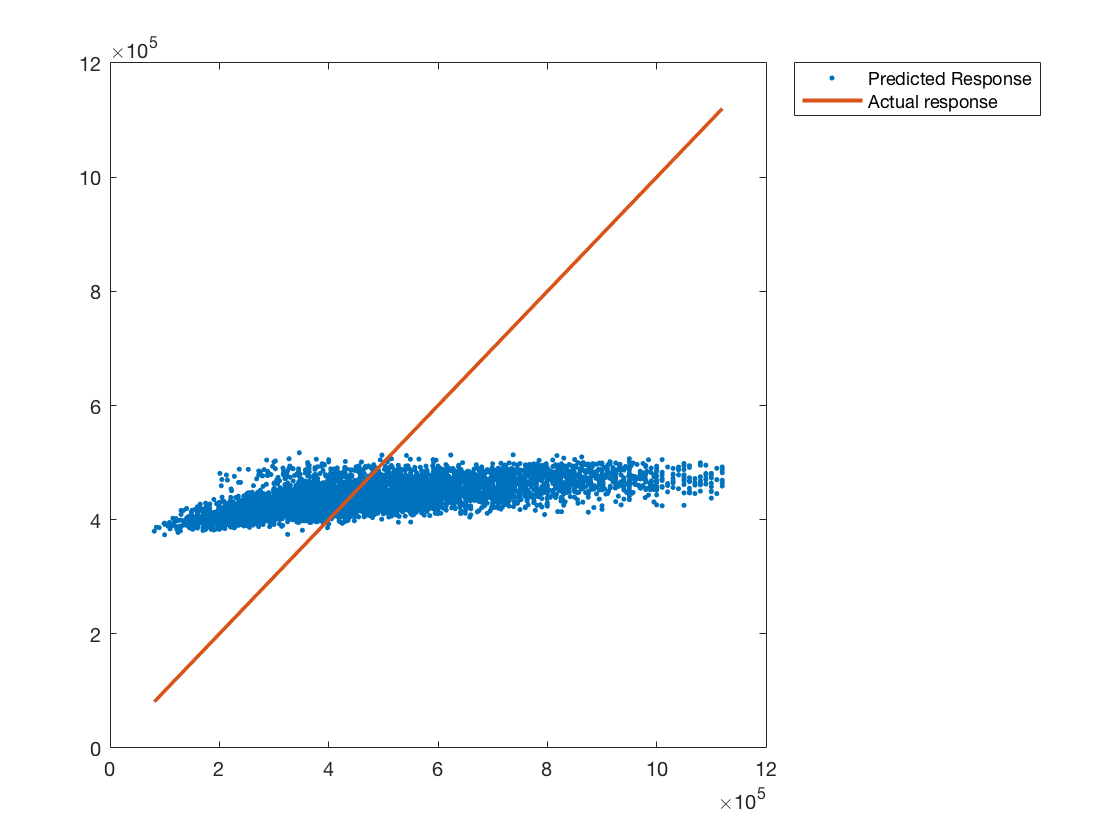

figure
plot(ytest,y_rsvm,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

#  PLS regression 

[xL,yl,xS,yS,BETA,PCTVAR] = plsregress(xtrain,ytrain,10)

xL = 	1.0e+05 *

    0.0005   -0.0001    0.0001   -0.0000   -0.0001   -0.0000   -0.0000    0.0000   -0.0001   -0.0001
    0.0006    0.0001    0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002    0.0001    0.0001
    0.8982    0.0028    0.1341   -0.0049   -0.1578    0.1876   -0.0553    0.0008   -0.0000   -0.0000
    0.9465   -4.0604   -0.0665    1.1817   -0.1521    0.0015    0.0002   -0.0001    0.0000    0.0000
    0.0003    0.0003   -0.0002   -0.0000    0.0000   -0.0000   -0.0001   -0.0002    0.0001    0.0000
    0.7543    0.0220   -0.3651   -0.0408   -0.0743   -0.0958    0.0480   -0.0007   -0.0000    0.0000
    0.0825   -0.0101    0.4029    0.0113   -0.1924   -0.1157    0.0566   -0.0007    0.0000    0.0000
   -0.0164    0.0143    0.0091    0.0019   -0.0034    0.0196    0.0524   -0.0254    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001
    0.0001   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001    

yl = 	1.0e+07 *

    1.4388    0.3366    0.3236    0.0389    0.0940    0.1516    0.3071    0.2427    0.6381    0.3108


xS =     0.0040    0.0008   -0.0019   -0.0037   -0.0107    0.0057    0.0087    0.0022   -0.0071    0.0040
   -0.0042    0.0054    0.0119    0.0005   -0.0108    0.0010    0.0023   -0.0059   -0.0005    0.0098
   -0.0026   -0.0018   -0.0051    0.0012    0.0015   -0.0005   -0.0022   -0.0047    0.0032    0.0017
   -0.0016   -0.0003   -0.0039    0.0009    0.0049   -0.0033   -0.0059   -0.0060    0.0281    0.0038
   -0.0007    0.0013   -0.0028    0.0005    0.0082   -0.0065   -0.0106    0.0018   -0.0073   -0.0038
   -0.0090   -0.0082   -0.0019   -0.0010    0.0075    0.0046    0.0141   -0.0153   -0.0014   -0.0013
   -0.0040   -0.0018    0.0112   -0.0024   -0.0009    0.0002    0.0067   -0.0074   -0.0056   -0.0028
    0.0015    0.0012   -0.0028   -0.0034    0.0093   -0.0051   -0.0063   -0.0040   -0.0100   -0.0011
    0.0098   -0.0030    0.0060    0.0023    0.0012    0.0282   -0.0158    0.0114   -0.0036    0.0017
   -0.0100    0.0013    0.0029    0.0005   -0.0002    0.0015    0.0035    0.0021    0.

yS = 	1.0e+12 *

    0.8748    0.0091    0.0004    0.0024    0.0072    0.0269    0.0278   -0.0431   -0.1468    0.0688
    1.8244    0.6314    0.5486    0.0509    0.1228    0.2134    0.4277    0.3210    0.9353    0.4652
    0.4719    0.2357    0.2464    0.0361    0.0868    0.1378    0.2815    0.2389    0.7008    0.2774
   -1.3445   -0.2357   -0.2236   -0.0219   -0.0533   -0.0928   -0.1728   -0.0926   -0.1505   -0.6315
   -3.1610   -0.7072   -0.6937   -0.0799   -0.1932   -0.3233   -0.6247   -0.4151   -1.1189   -0.4010
   -2.6668   -0.1898   -0.0927   -0.0088   -0.0208   -0.0443   -0.1114   -0.1931   -0.2712   -0.1043
   -3.5638   -0.6422   -0.5973   -0.0859   -0.2066   -0.3318   -0.6733   -0.5821   -1.4157   -0.5775
   -2.2186   -0.5896   -0.5799   -0.0663   -0.1588   -0.2694   -0.5218   -0.3655   -0.8987   -0.2395
    2.6661    0.1496    0.1763    0.0136    0.0320    0.0500   -0.0301    0.0938    0.0704    0.1063
   -0.1324    0.4515    0.4197    0.0468    0.1129    0.1823    0.3622    

BETA = 	1.0e+07 *

   -1.1712
   -0.0015
    0.0021
    0.0000
   -0.0000
    0.0012
   -0.0000
    0.0000
    0.0000
    0.0062


PCTVAR =     0.0911    0.7996    0.0097    0.0900    0.0070    0.0022    0.0003    0.0000    0.0000    0.0000
    0.3256    0.0178    0.0165    0.0002    0.0014    0.0036    0.0148    0.0093    0.0640    0.0152


yPLS=[ones(size(xtest,1),1) xtest]*BETA;
MSEpls=immse(ytest,yPLS)

MSEpls = 2.2242e+10

Let's graph the predicted value and the real value to compare

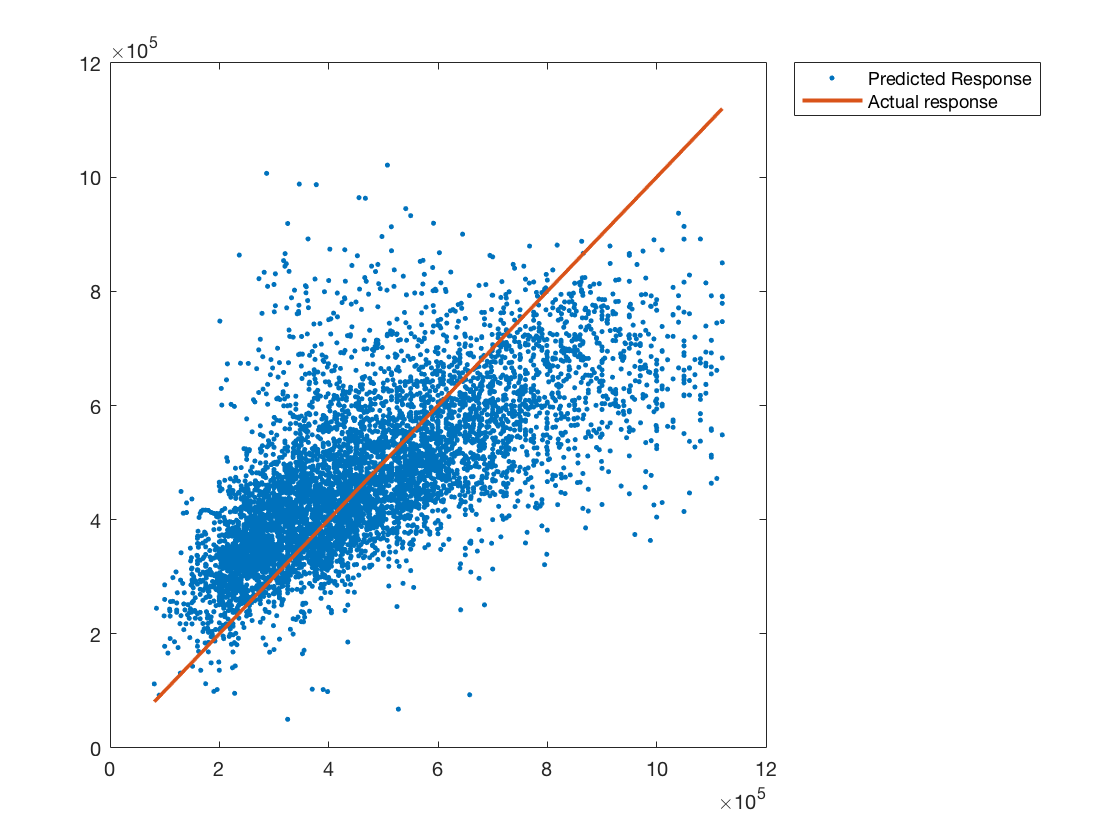

figure
plot(ytest,yPLS,".")
hold on
plot(ytest,ytest,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

# Compare MSE of all models

***PCR models (from 2 to 10 PCs)***

MSEpcr2comp

MSEpcr2comp = 4.2374e+10

MSEpcr3comp

MSEpcr3comp = 2.8270e+10

MSEpcr4comp

MSEpcr4comp = 2.7456e+10

MSEpcr5comp

MSEpcr5comp = 2.7283e+10

MSEpcr6comp

MSEpcr6comp = 2.7198e+10

MSEpcr7comp 

MSEpcr7comp = 2.6726e+10

MSEpcr8comp 

MSEpcr8comp = 2.5885e+10

MSEpcr9comp

MSEpcr9comp = 2.3856e+10

MSEpcr10comp

MSEpcr10comp = 2.3404e+10

***Linear regression models (default model, adjusted model and step-adjusted model)***

MSEtest 

MSEtest = 1.8732e+10

MSEtest2 

MSEtest2 = 1.9044e+10

MSEtest3 

MSEtest3 = 1.7542e+10

*** Regression decision tree model***

MSEtree

MSEtree = 1.8692e+10

***Support vector machine regression model***

MSEsvm

MSEsvm = 3.7268e+10

***Partial Least Squares (PLS) regression model***

MSEpls

MSEpls = 2.2242e+10

Among all the built models, based on MSE, MSEtest3 (step-adjusted model) has the smallest value. Therefore, this model predicts most correctly. 

Barplot comparation the MSE value of 5 models: PCR with 10 PCs model, Step-Adjusted Model, Regression Decision Tree Model, Suppport Vector Machine Model and PLS Regression Model. 

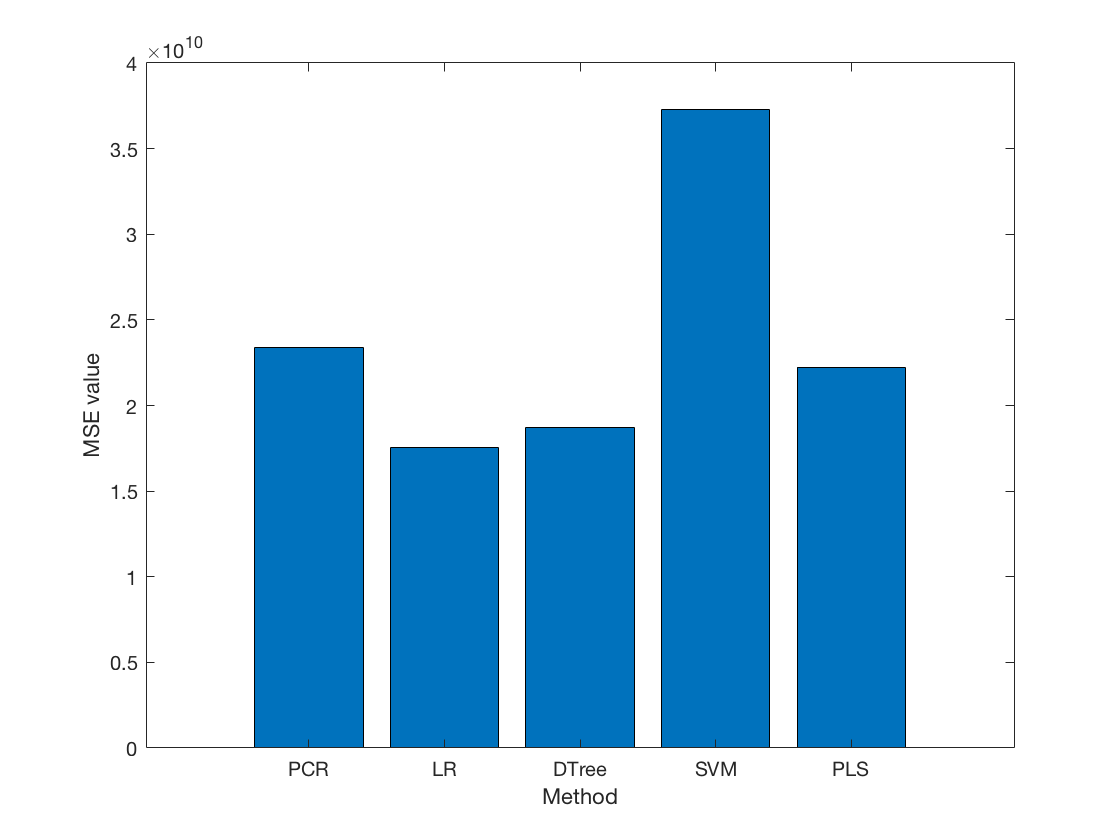

bar([MSEpcr10comp MSEtest3 MSEtree MSEsvm MSEpls])
xlabel('Method')
ylabel('MSE value')
xticklabels({'PCR','LR','DTree','SVM','PLS'})